# Fourier Analysis of Signals Using DFT (250 Points)

**Dear Student, **

**At the end of this exercise, you will be able to **

- **find out an estimate of frequency content of a discrete-time sequence,  **

- **comment on resolution and leakage of a window and its impact on the frequency analysis, and **

- **compare different types of windows.**

- **use short-term Fourier transform and obtain power spectral density of a signal. **

Let $x[n] =  A_0\cos(w_0n) +  A_1\cos(w_1n), n \in \mathbb{Z}$ be the discrete-time signal obtained by sampling $x(t)$with sampling frequency $T_s$. 

Write down possible expressions for $x(t)$ here:  $\textrm{ENTER}\;\textrm{YOUR}\;\textrm{ANSWER}\;\textrm{HERE}\ldotp$ 

x(t) = $A_0 cos(\Omega_0t) + A_1cos(\Omega_1t)$,where $\omega = \Omega  T_s$.

Usually, we cannot obtain the sequence $x[n]$for all the time duration, i.e., for $-\infty $to $+\infty
$. Further, even if you are able to collect a large number of samples, we will not be able to compute its DFT for frequency analysis.  Let us assume that we have $x[n]$values available for $0\leq n\leq L-1$only using which we are required to do frequency analysis. One way to go forward is, we assume that $x[n]=0$ for $n\notin \{0,L-1\}$.  That is, we have the windowed sequence, $v[n]$, defined as follows:$v[n] = x[n]w[n]$, where $w[n] = 1$for $0\leq n\leq L-1$ and $w[n] =0$, otherwise. This window is called as the rectangular window. 

#### Coding Question (10 points)

Write a code to get $x[n], w[n] $and $v[n]$

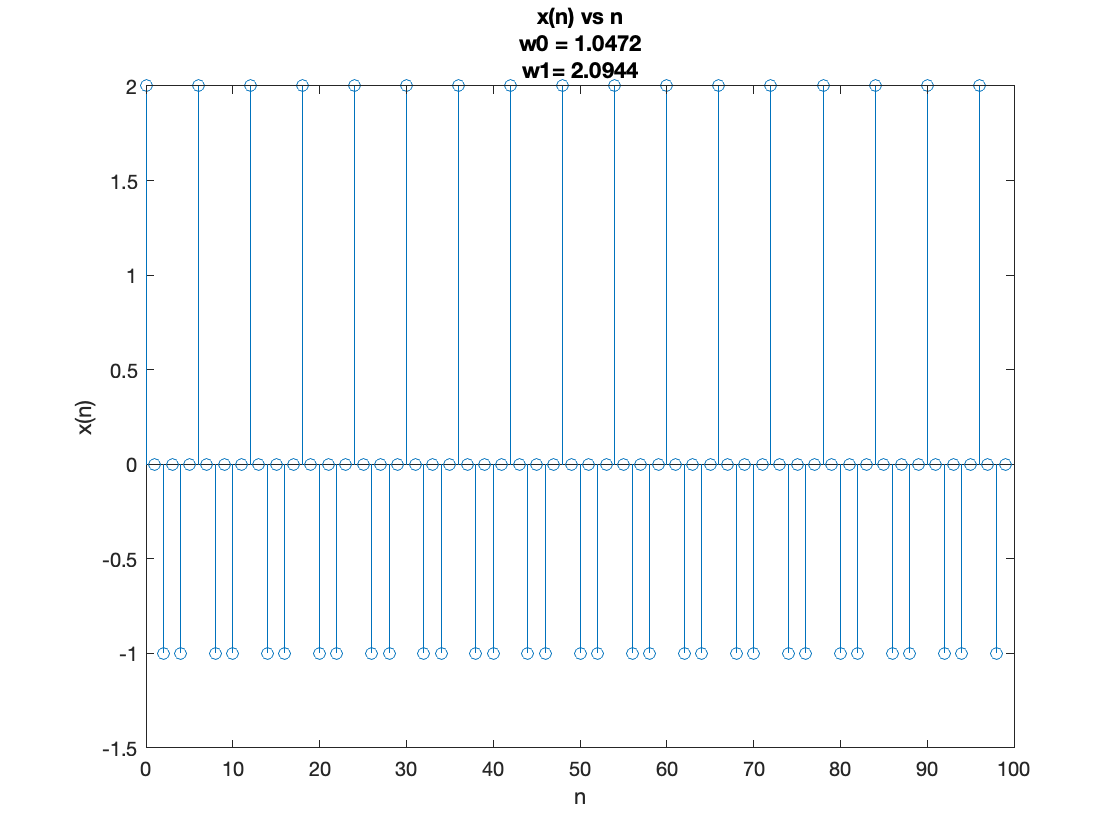

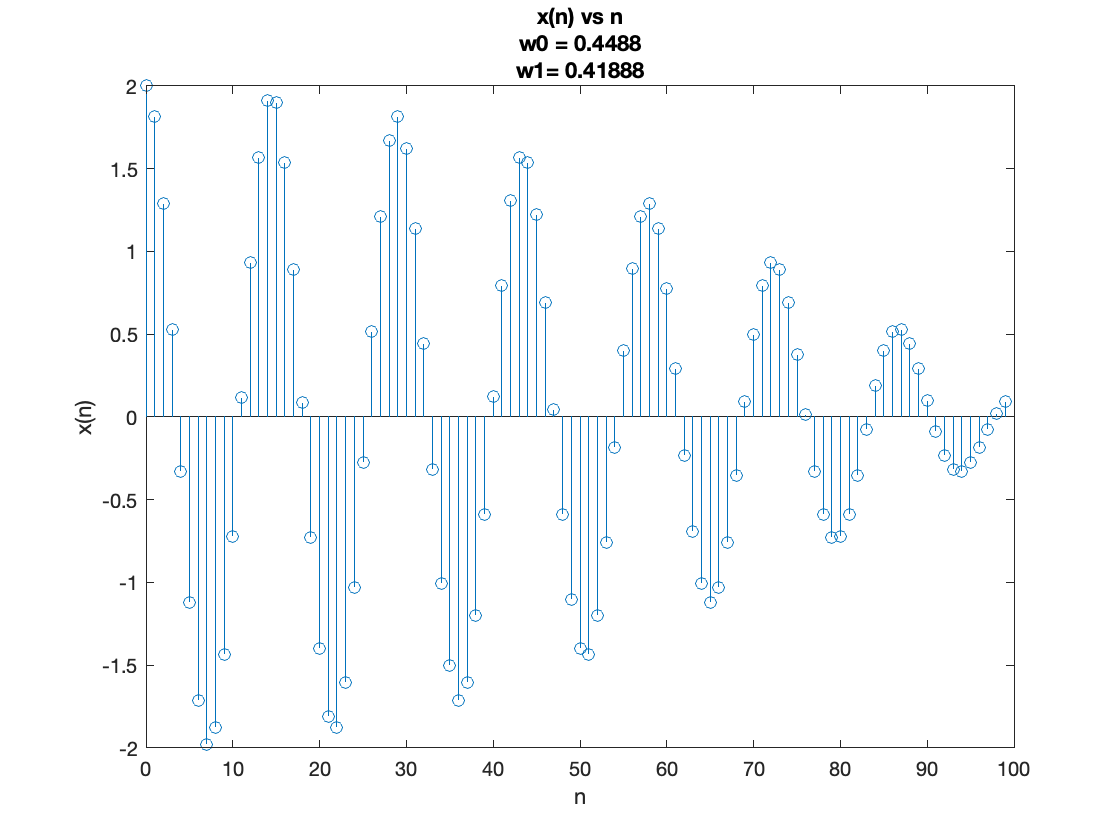

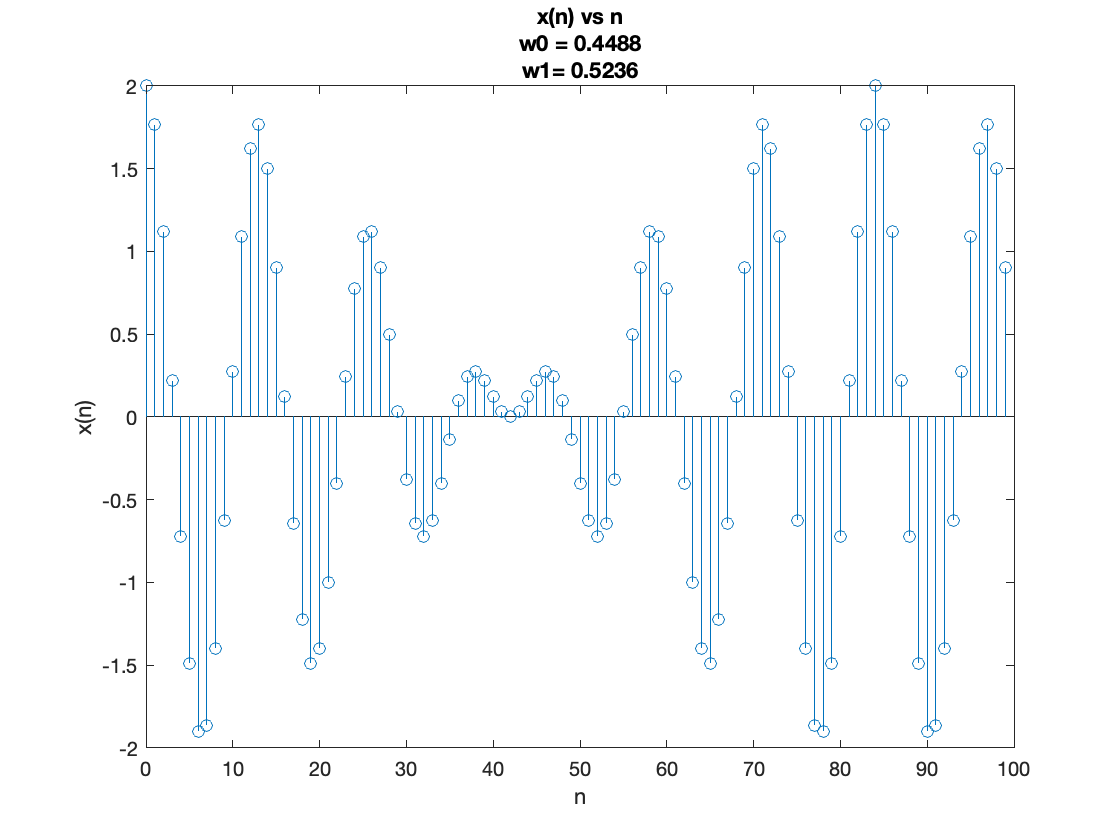

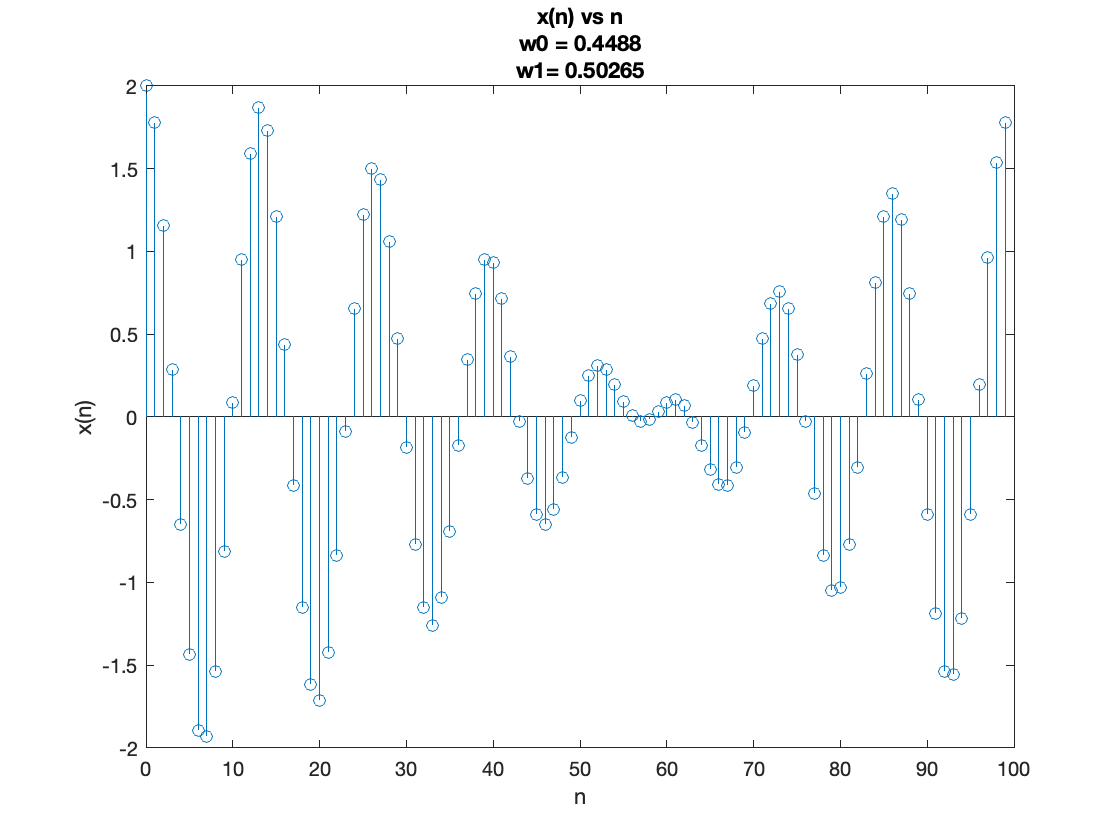

w0 = [2*pi/6;2*pi/14;2*pi/14;2*pi/14];
w1 = [2*pi/3;2*pi/15;2*pi/12;4*pi/25];
A1 = 1;
A2 = 1;
L =  64;   % Window length
num = 100;
n = 0:1:num-1;
x = [];             % EXERCISE: Construct x[n] defined above  
x = cos(w0*n)+cos(w1*n);
for i=1:size(x,1)
    figure();
    stem(n,x(i,:))
    xlabel('n')
    ylabel('x(n)')
    title({['x(n) vs n'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

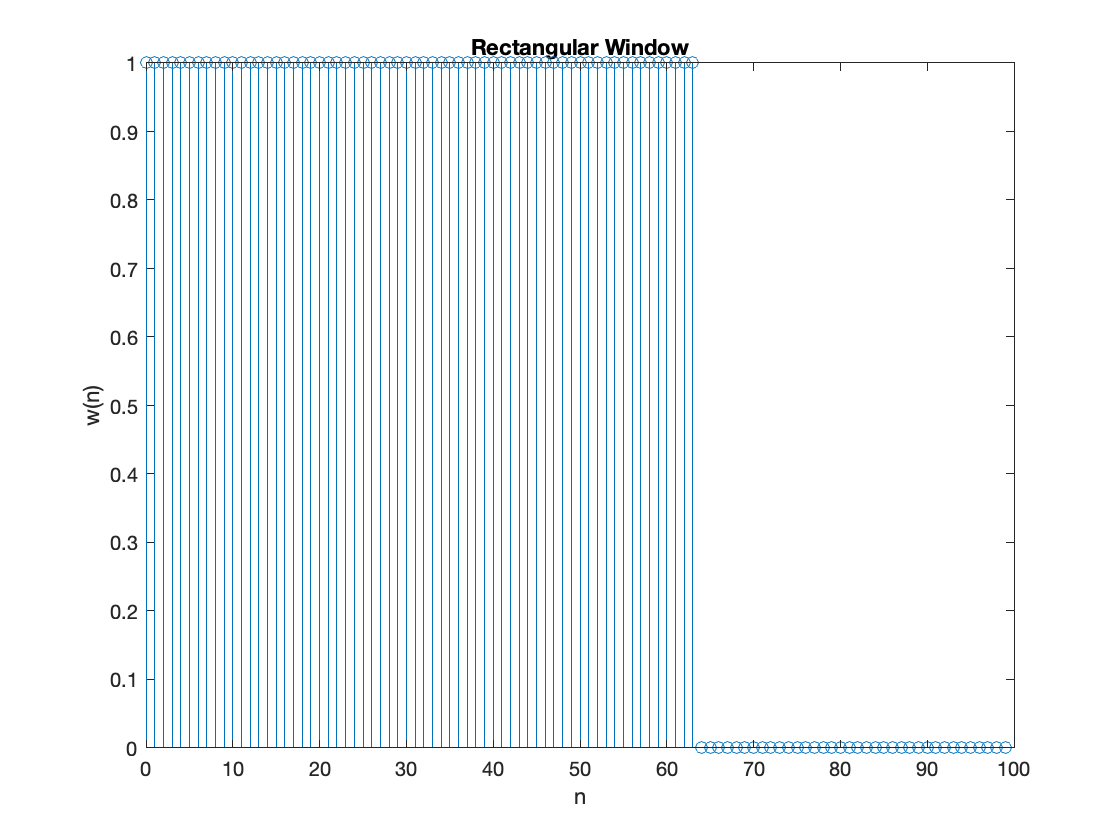

size(x);
rectWindow = [];       % EXERCISE Define a rectangular window of length L, w[n]
rectWindow = [ones(L,1);zeros(num-L,1)];

v =  []; % EXERCISE: Compute the windowed sequence, v[n]
v = x.*rectWindow';
stem(n,rectWindow)
xlabel('n')
ylabel('w(n)')
title('Rectangular Window')

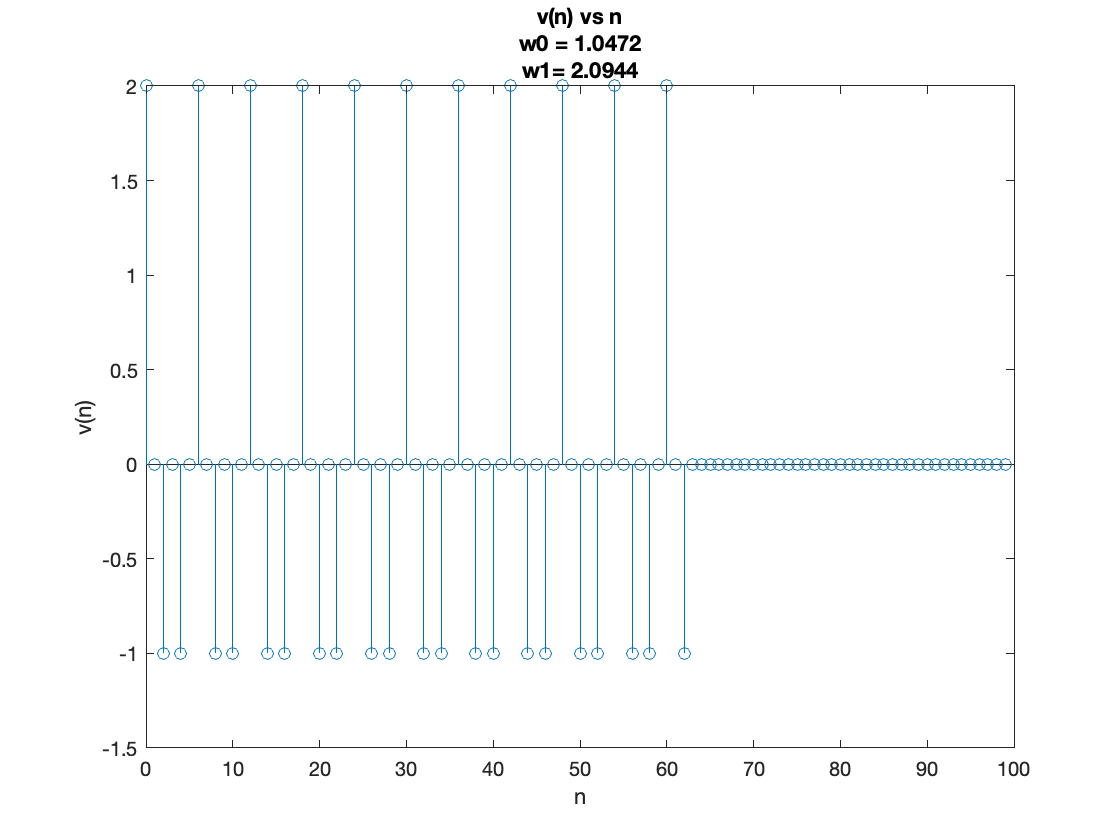

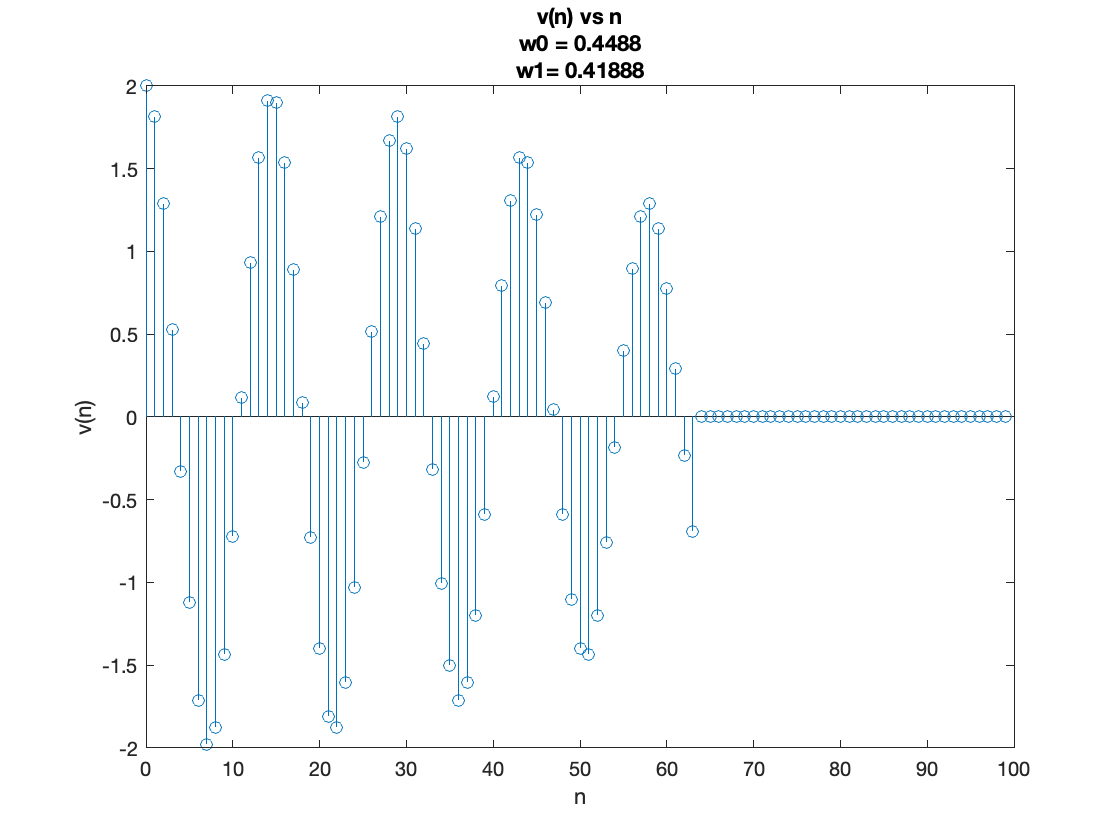

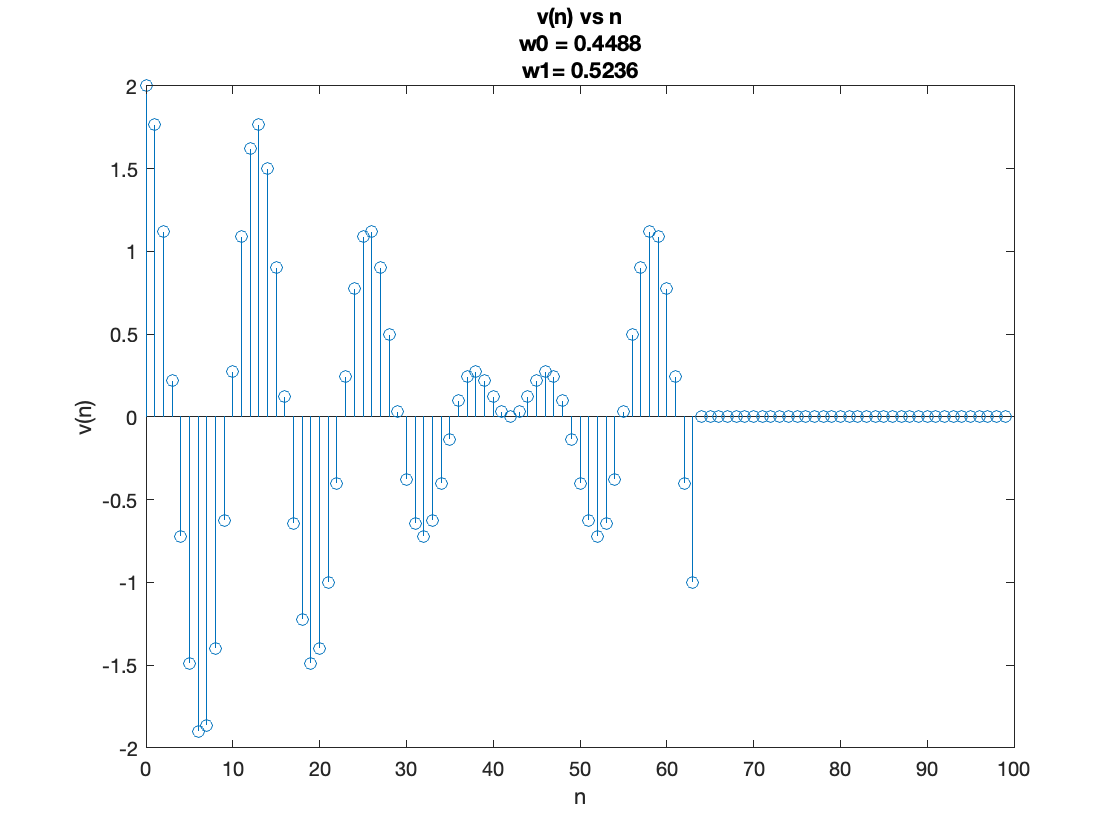

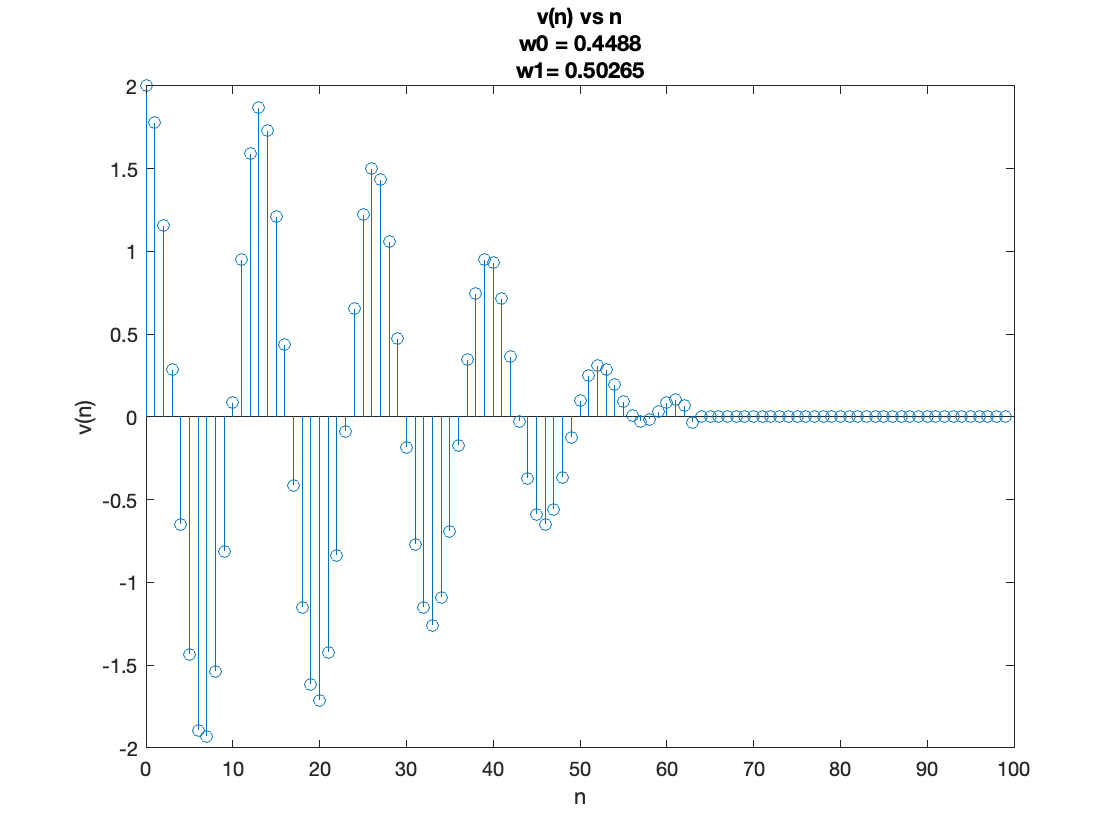

for i=1:size(x,1)
    figure();
    stem(n,v(i,:))
    xlabel('n')
    ylabel('v(n)')
    title({['v(n) vs n'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

Now, we will compute its DFT using the Matlab in-built function ([fft](https://in.mathworks.com/help/matlab/ref/fft.html)). 

#### Coding Question (10 points)

Compute $N$-point DFT, $V[k]$ of $v[n]$ and plot $V[k]$ from $k\in [0, N-1]$

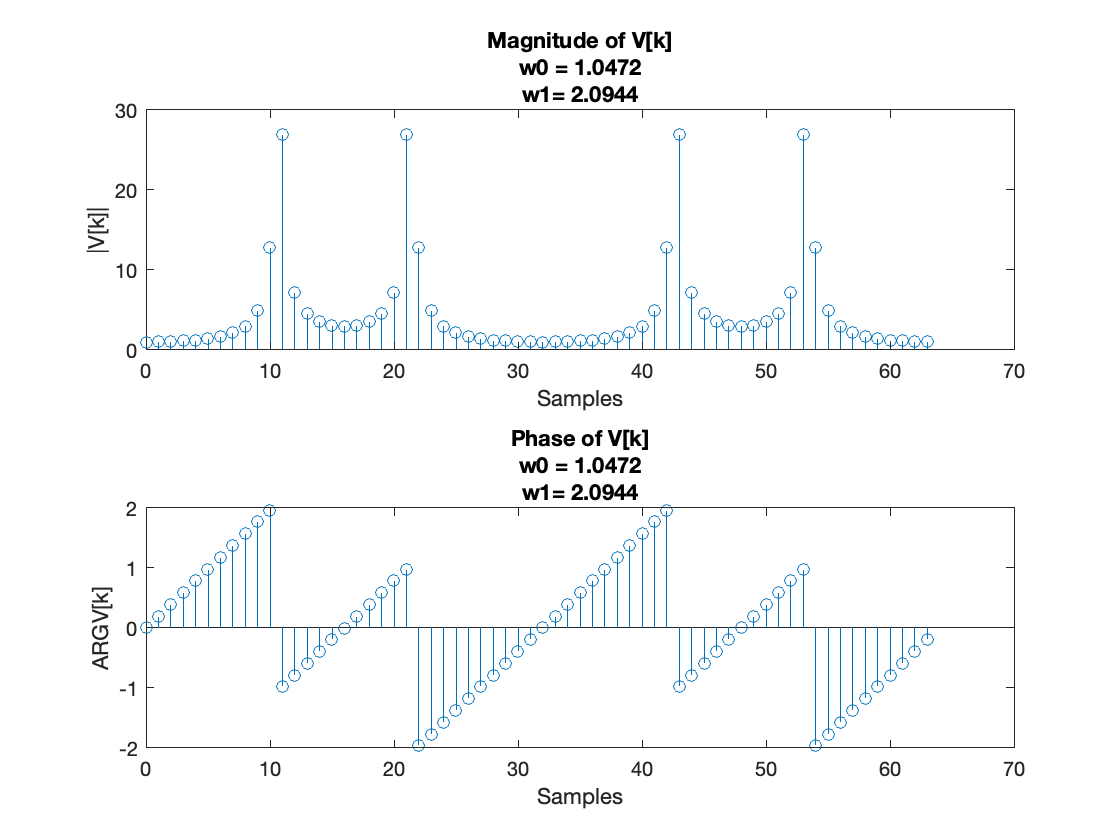

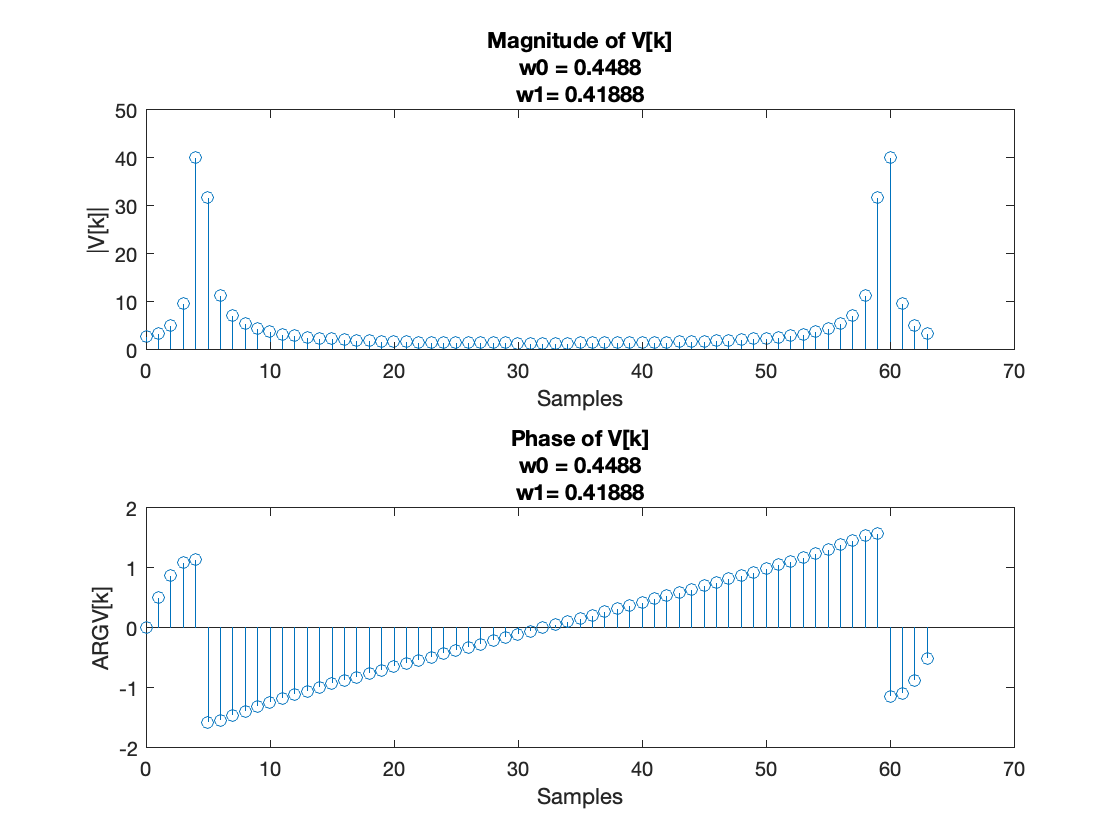

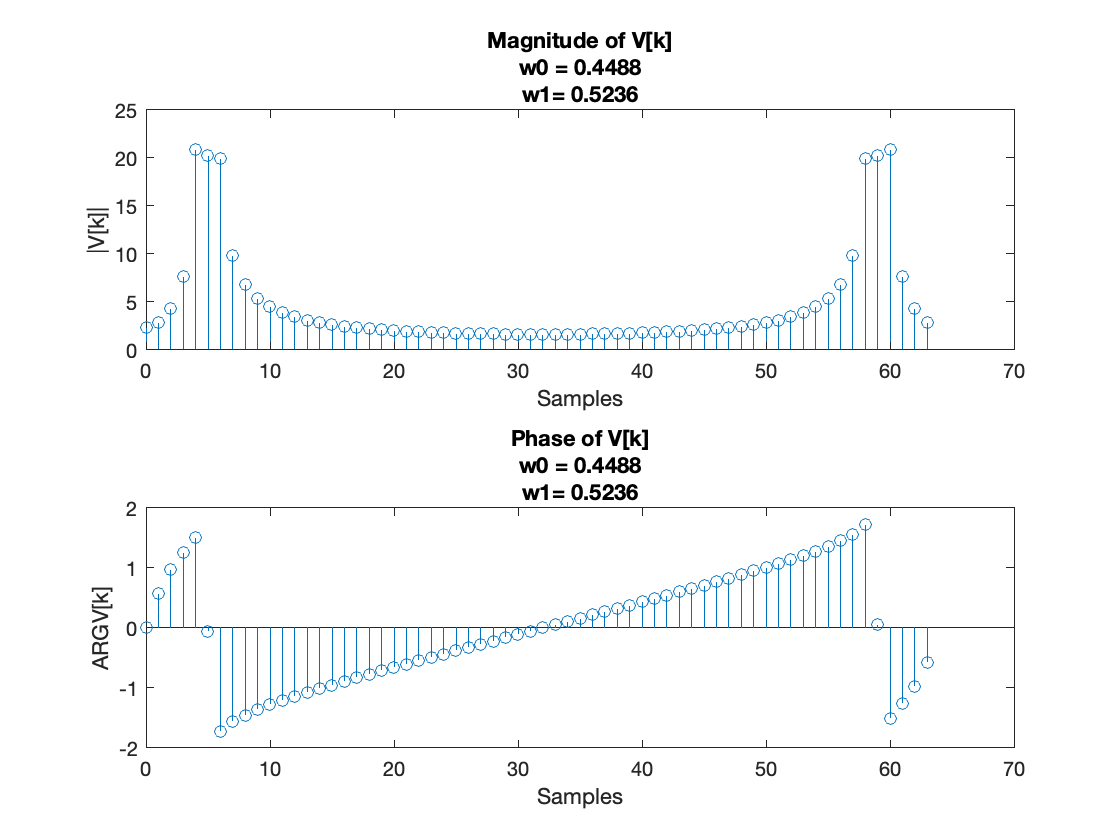

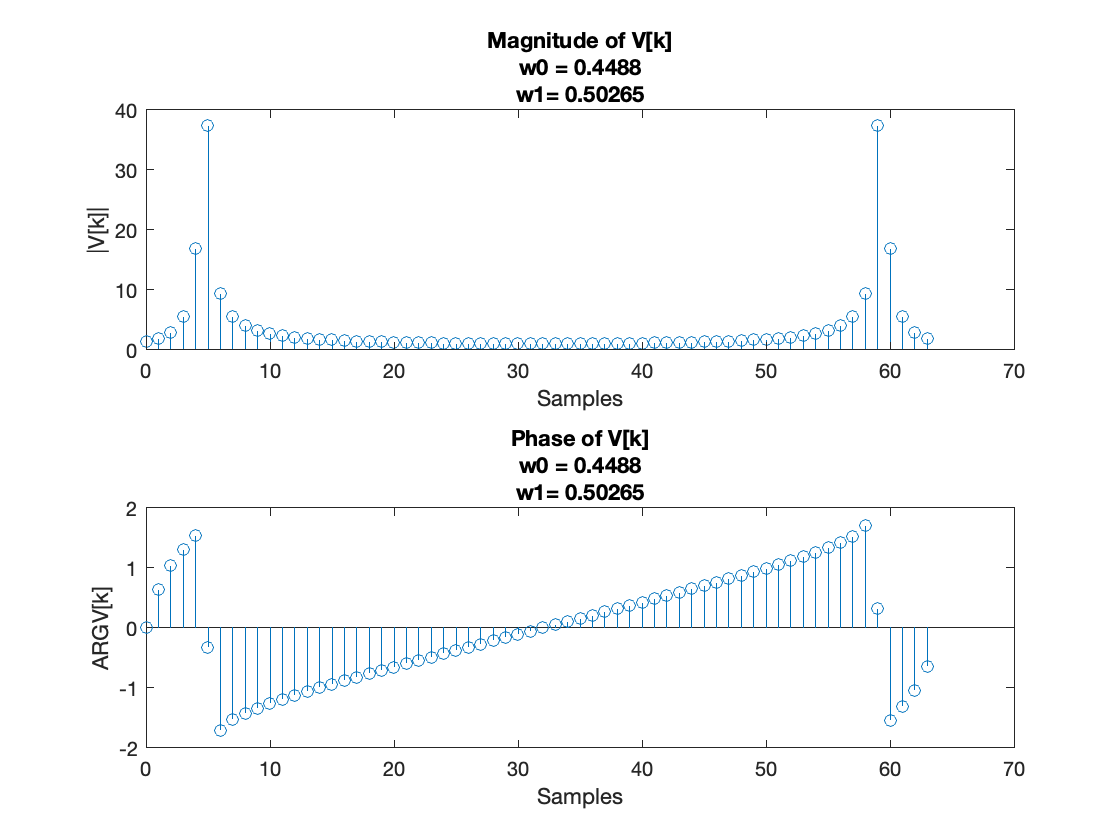

N = [L]; % EXERCISE: Define a suitable N
 
V = []; % EXERCISE: Compute N-point DFT
for i=1:size(x,1)
    V = fft(v(i,:),N);
    figure();
    subplot(2,1,1);
    stem([0:N-1], [abs(V)]); %  EXERCISE: Plot Magnitude of V
    xlabel('Samples')
    ylabel('|V[k]|')
    title({['Magnitude of V[k]'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
    
    subplot(2,1,2); 
    stem([0:N-1], [angle(V)]); %  EXERCISE: Plot Phase of V
    xlabel('Samples')
    ylabel('ARG{V[k]}')
    title({['Phase of V[k]'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

It is bit difficult to read the above plots as we do not readily see which samples correspond to which discrete-time frequency. Hence, let us try to view the DTFT of v[n] (approximate). Let us first compute the DTFT of $w[n]$.

#### Coding Question (10 points)

Compute the DTFT of w[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

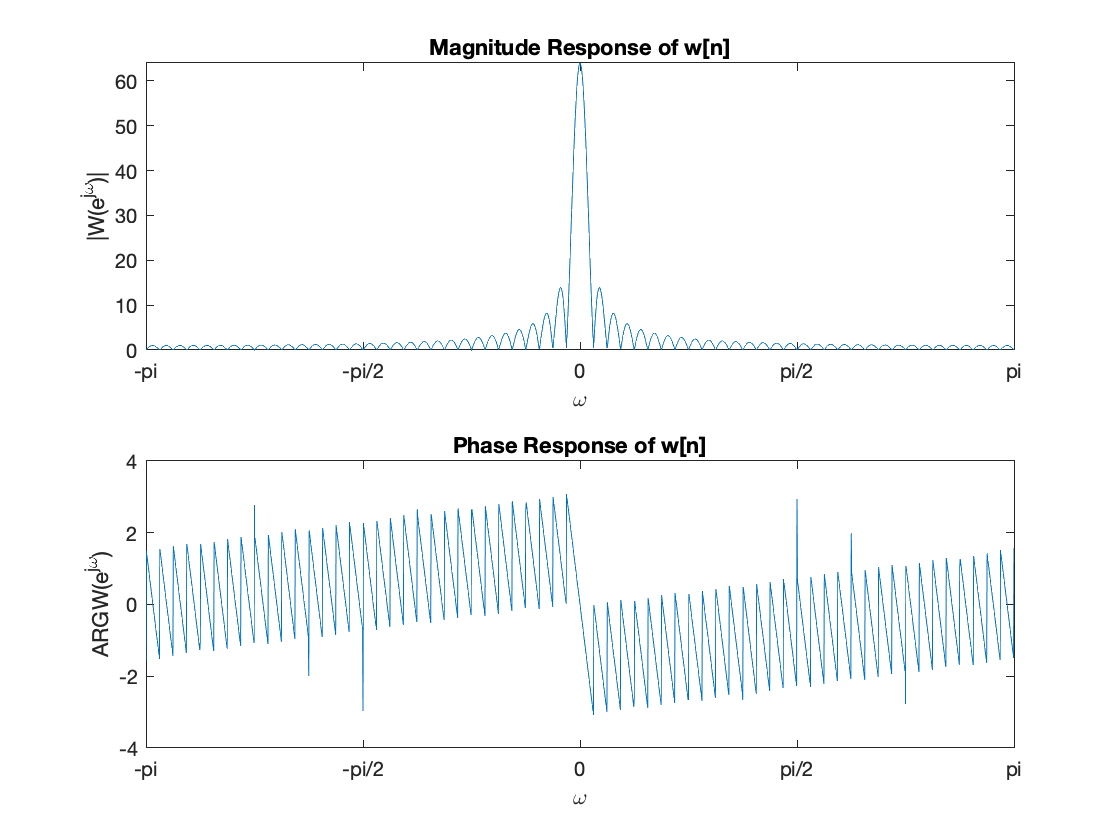

N = [1000]; % EXERCISE: Define a suitable N
W = []; % EXERCISE: Compute N-point DFT
omega = -pi:pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
W = zeros(length(omega),1);
for i=1:length(omega)
    for j=1:length(rectWindow)
        W(i) = W(i) + rectWindow(j)*exp(-omega(i)*1j*(j-1));
    end
end
figure();
subplot(2,1,1);
plot([omega], [abs(W)]); %  EXERCISE: Plot Magnitude  of V
xlim([-pi,pi])
set(gca,'XTick',-pi:pi/2:pi)
set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})
xlabel('\omega')
ylabel('|W(e^{j\omega})|')
title('Magnitude Response of w[n]')

subplot(2,1,2); 
plot([omega], [angle(W)]); %  EXERCISE: Plot Magnitude  of V
xlim([-pi,pi])
set(gca,'XTick',-pi:pi/2:pi)
set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})
xlabel('\omega')
ylabel('ARG{W(e^{j\omega})}')
title('Phase Response of w[n]')

#### Coding Question 10 points)

Compute the DTFT of v[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

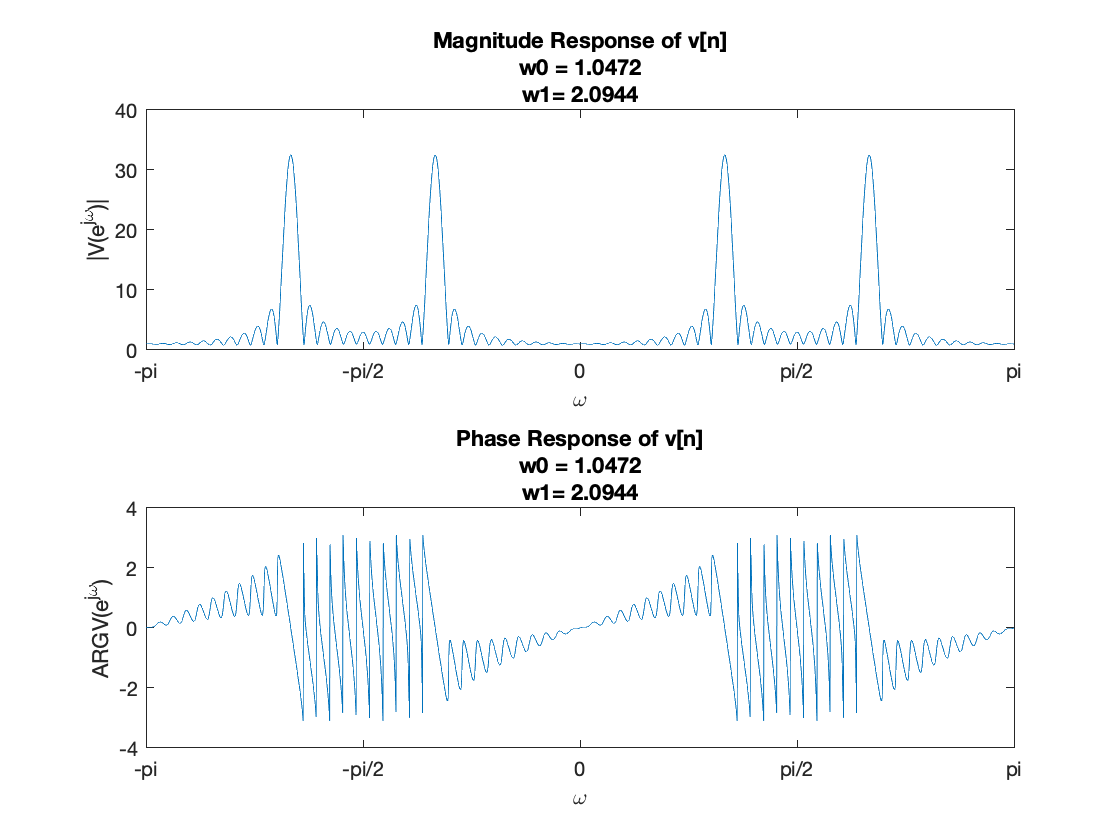

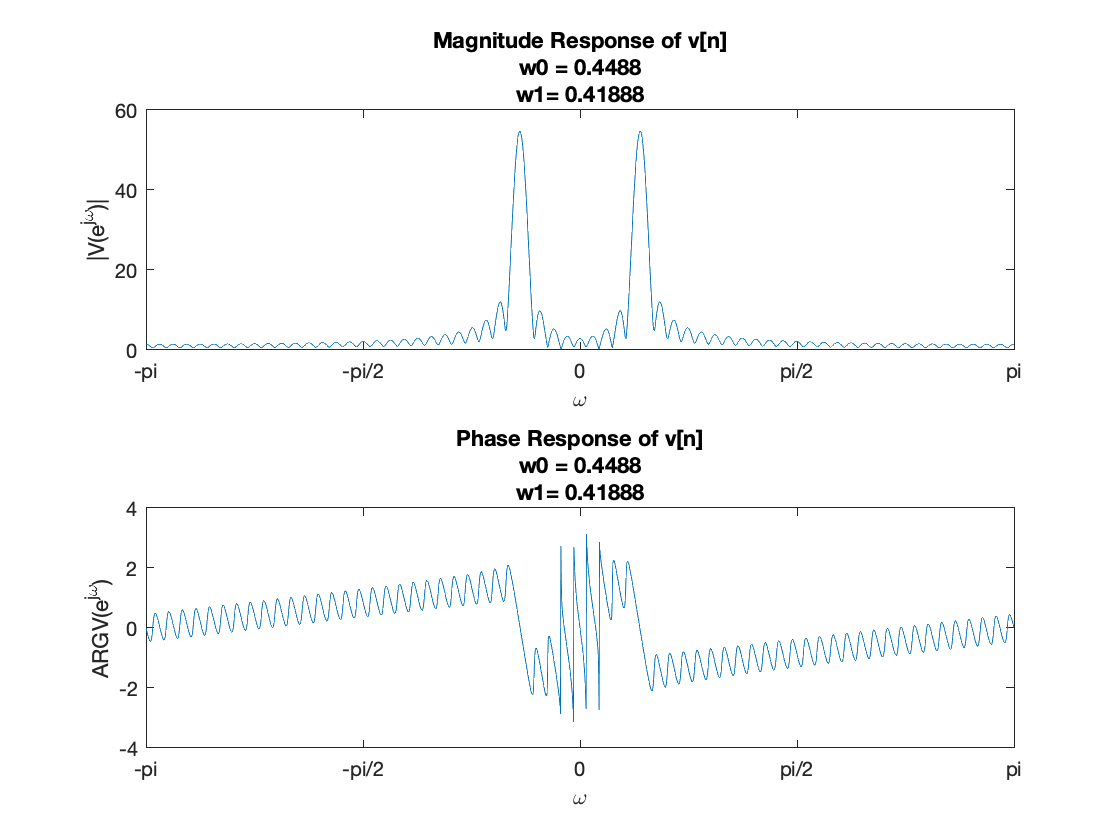

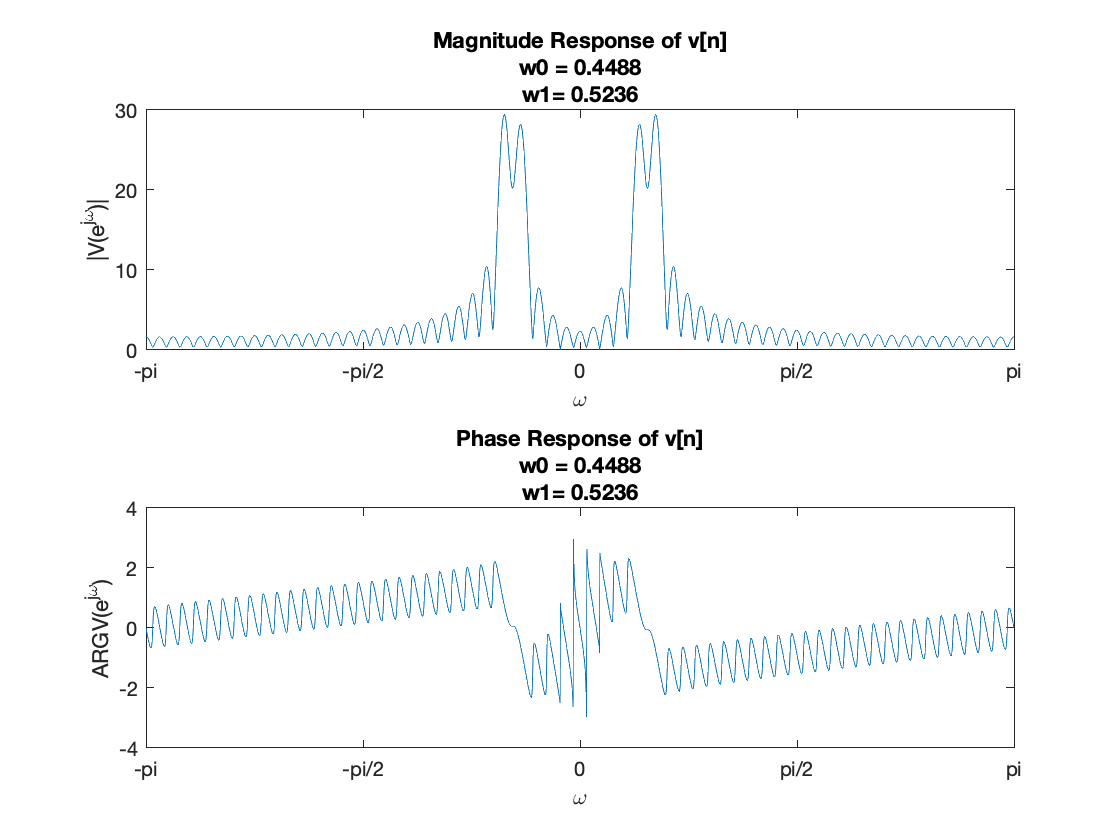

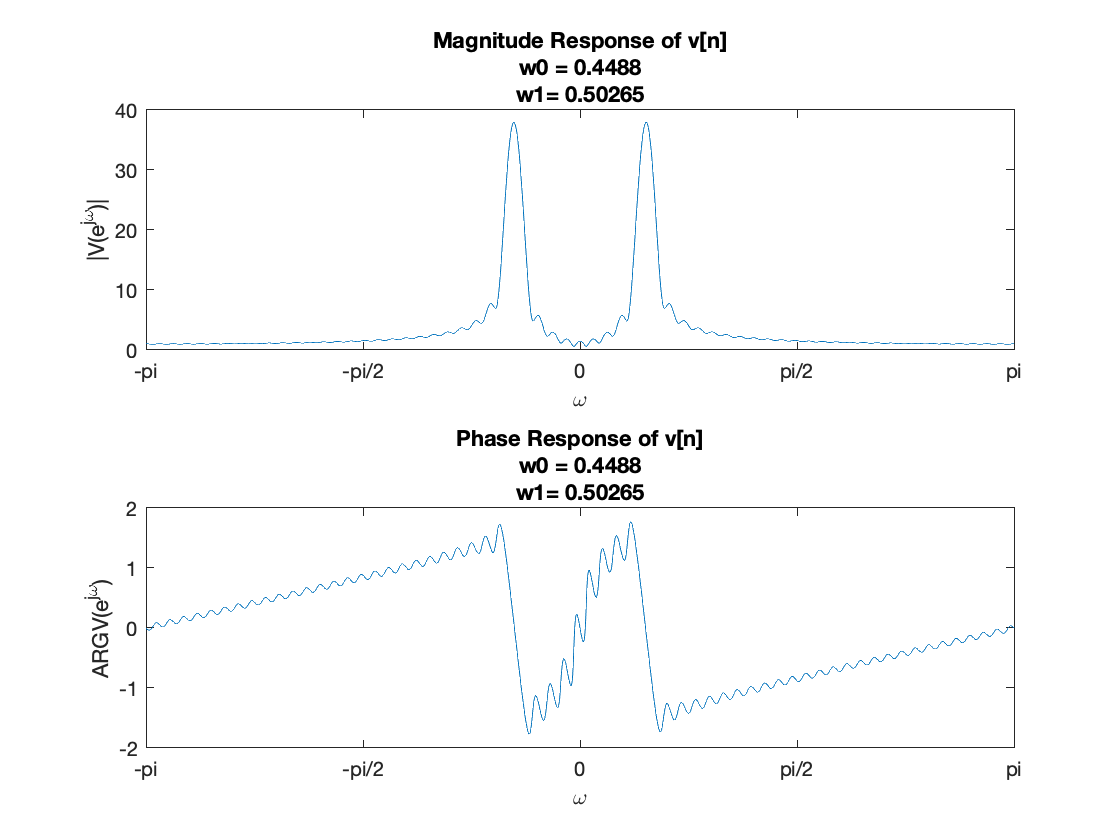

N = [1000]; % EXERCISE: Define a suitable N
omega = -pi:pi/N:pi;% EXERCISE: Compute sample points of discrete-time frequency
V = []; % EXERCISE: Compute N-point DFT
for n=1:size(x,1)
    V = zeros(length(omega),1);
    for i=1:length(omega)
        for j=1:length(rectWindow)
            V(i) = V(i) + v(n,j)*exp(-omega(i)*1j*(j-1));
        end
    end
    figure();
    subplot(2,1,1);
    plot([omega], [abs(V)]); %  EXERCISE: Plot Magnitude  of V
    xlim([-pi,pi])
    set(gca,'XTick',-pi:pi/2:pi)
    set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title({['Magnitude Response of v[n]'];['w0 = ',num2str(w0(n))];['w1= ',num2str(w1(n))]})
    
    subplot(2,1,2); 
    plot([omega], [angle(V)]); %  EXERCISE: Plot Magnitude  of V
    xlim([-pi,pi])
    set(gca,'XTick',-pi:pi/2:pi)
    set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title({['Phase Response of v[n]'];['w0 = ',num2str(w0(n))];['w1= ',num2str(w1(n))]})
end

figure();

#### Coding Question  (10 points)

Now, suppose the $x(t)$ was sampled at sampling period of $T_s$, then plot $X(j\Omega)$, your estimate of the continuous-time Fourier transform of $x(t)$. 

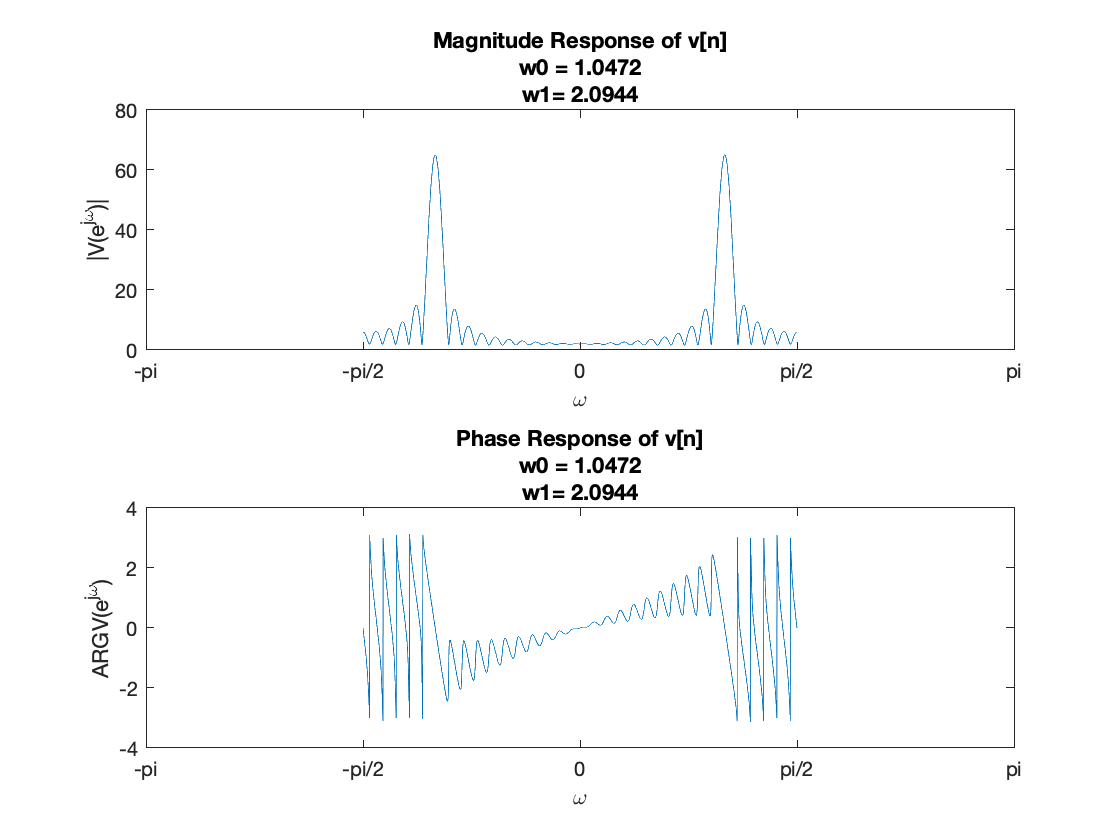

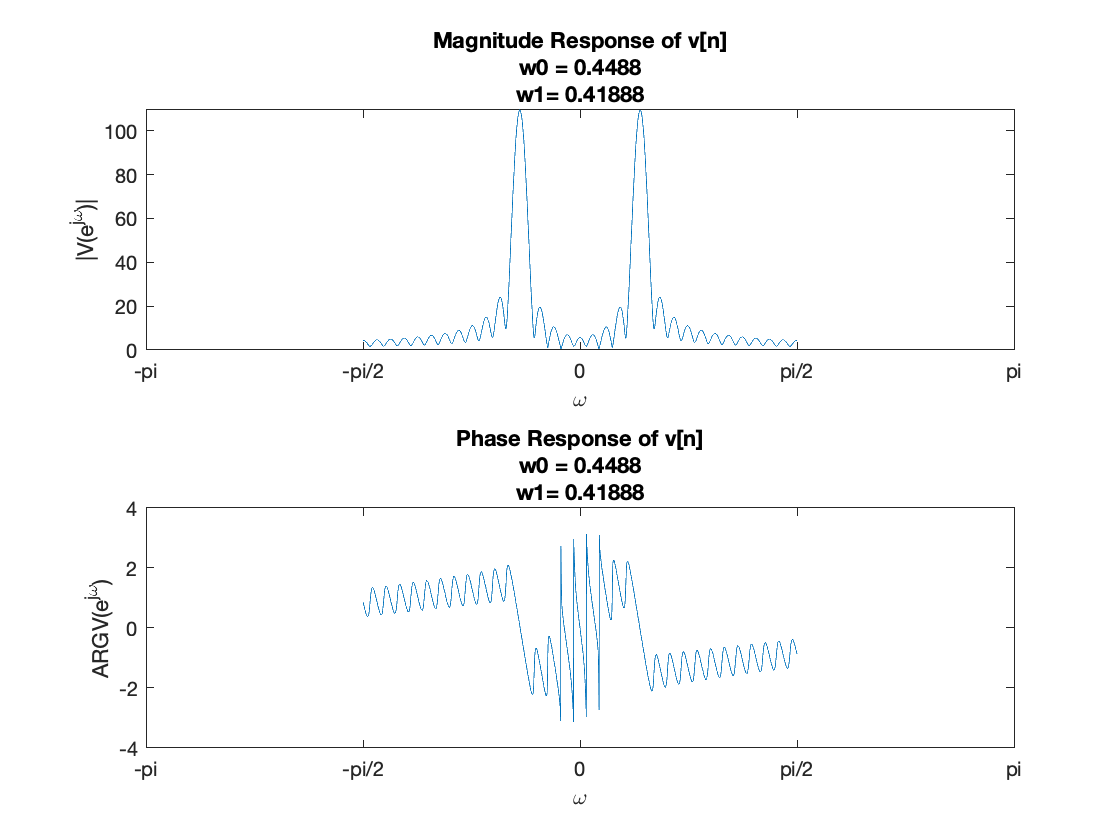

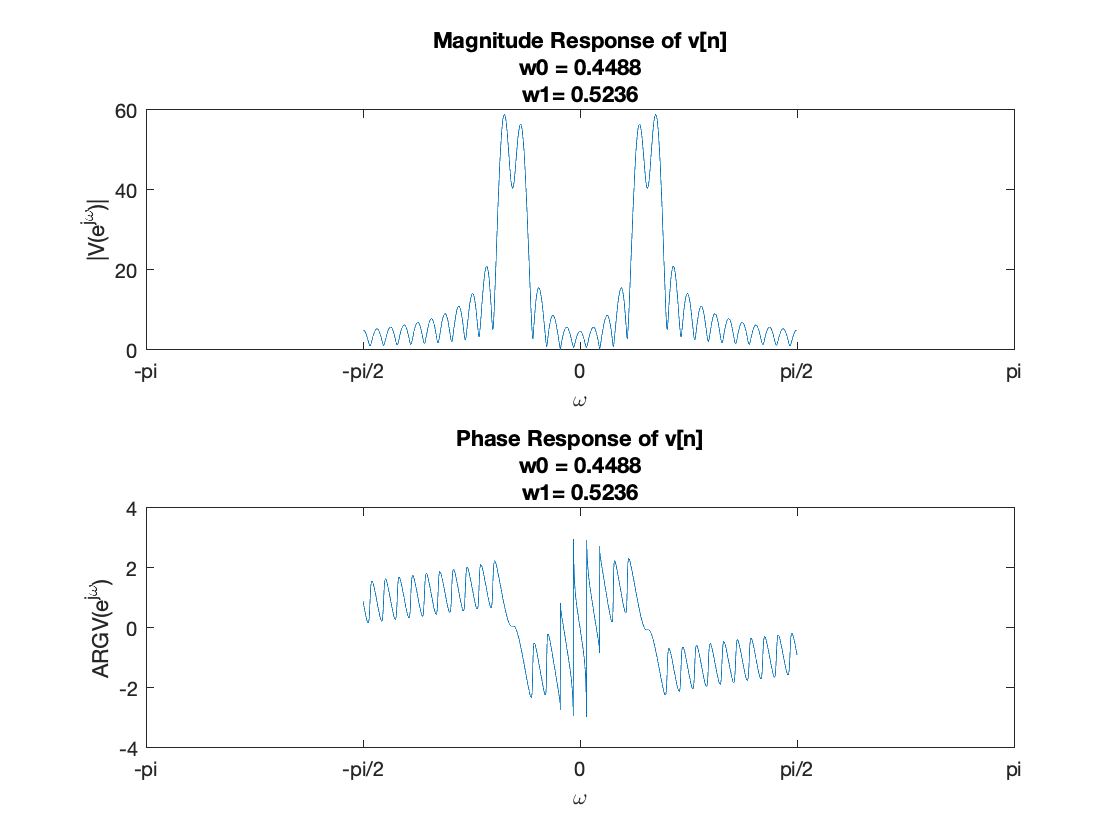

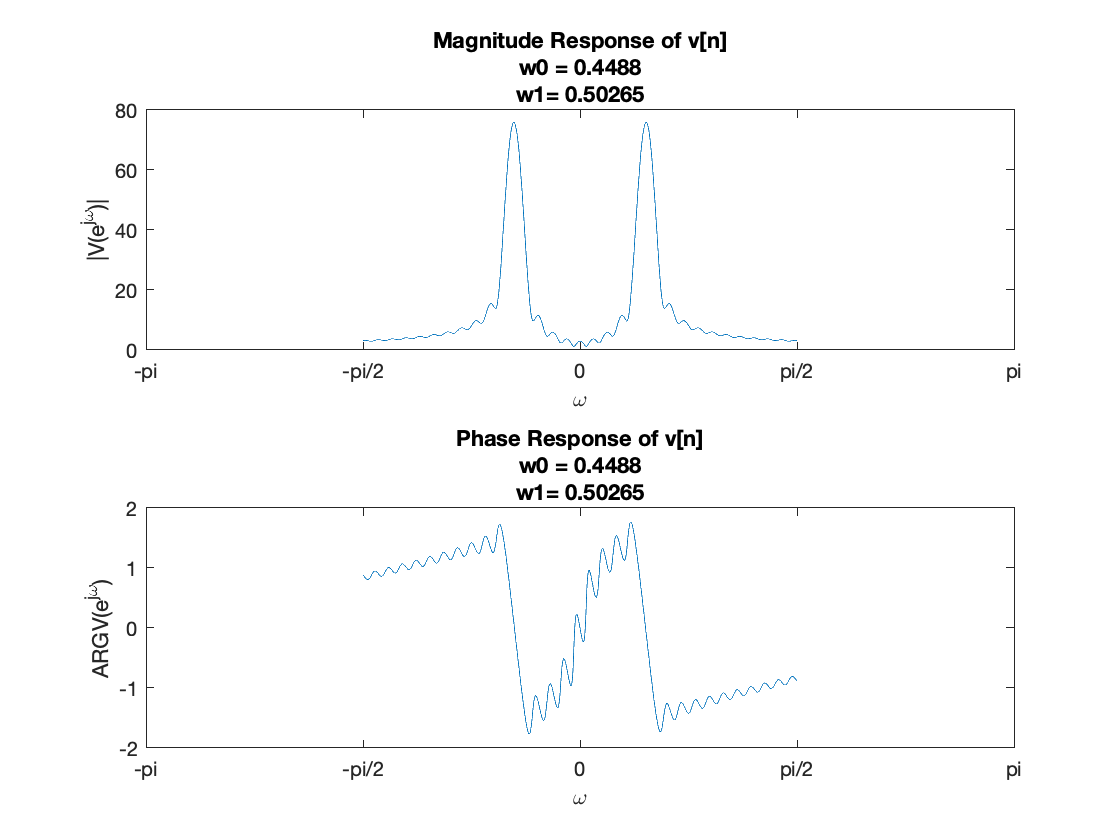

Ts = [2] ; % EXERCISE: Choose a sensible sampling frequency

Omega = [omega/Ts]; % EXERCISE: Construct continuous-time frequency from discrete-time frquency
X_jOmega = []; %EXERCISE:  Compute the continuous-time Fourier transform


for n=1:size(x,1)
    X_jOmega = zeros(length(Omega),1);
    for i=1:length(Omega)
        for j=1:length(rectWindow)
            X_jOmega(i) = X_jOmega(i) + v(n,j)*exp(-Omega(i)*1j*(j-1));
        end
        X_jOmega(i) = Ts*X_jOmega(i);
    end
    figure();
    subplot(2,1,1);
    plot([Omega], [abs(X_jOmega)]); %  EXERCISE: Plot Magnitude  of V
    xlim([-pi,pi])
    set(gca,'XTick',-pi:pi/2:pi)
    set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title({['Magnitude Response of v[n]'];['w0 = ',num2str(w0(n))];['w1= ',num2str(w1(n))]})
    
    subplot(2,1,2); 
    plot([Omega], [angle(X_jOmega)]); %  EXERCISE: Plot Magnitude  of V
    xlim([-pi,pi])
    set(gca,'XTick',-pi:pi/2:pi)
    set(gca,'XTickLabel',{'-pi','-pi/2','0','pi/2','pi'})
    xlabel('\omega')
    ylabel('ARG{V(e^{j\omega})}')
    title({['Phase Response of v[n]'];['w0 = ',num2str(w0(n))];['w1= ',num2str(w1(n))]})
end

figure();


#### Inference Question (40 points)

Now, repeat the above four questions for 

- 
$$w_0 = 2\pi/14, w_1 = 2\pi/15$$


- 
$$w_0 = 2\pi/14, w_1 = 2\pi/12$$


- 
$$w_0 = 2\pi/14, w_1 = 4\pi/25$$


- What do you observe on the number of peaks?  

- How does your observation change if you change $L$? 

- How does your observation change if you change $N$? 

- Do the amplitudes of $|V[k]|$reflect that of $|V(e^{j\omega})|$? Why? 

- Do the amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$?  Why? 

    * WRITE YOUR ANSWER HERE.*

*        I have plotted DTFT's and DFT's for all different omegas and inferred as follows:*

- *The number of peaks when a rectangular window is used depends on how close the frequency components are to each other,Here:*

                $w_0 =2\pi /3,w_1 =2\pi \;/6$: As in this case the frequencies are at a large gap($|w_0 - w_1| = \pi/3 \geq 4\pi/L $) from each other so clearly 4 peaks i.e two on each side of zero frequency components were visible.

                $w_0 =2\pi /14,w_1 =2\pi \;/15$:In this case gap $|w_0 - w_1| = \pi/110 \leq 4\pi/L $for the values of L taken and hence only 2 peaks were visible as both peaks get mixed due to smaller gap then $4\pi/L$.

                $w_0 =2\pi /14,w_1 =2\pi \;/12$:In this case gap $|w_0 - w_1| = \pi/99 \leq 4\pi/L $for the values of L taken and here we can see peaks which are superimposed over each other and we can obsereve 4 peaks .

 ${\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;w}_0 =2\pi /14,w_1 =2\pi \;/12$:In this case gap $|w_0 - w_1| = 12\pi/700 \leq 4\pi/L $for the values of L taken and here we can see peaks which are superimposed over each other and we can obsereve 2 peaks clearly.

- The observation made while changing L was that increasing L changes the main lobe width,makes it narrower, but increases the leakage through side lobes.So more is the L the better the peaks can be distinguished by each other but side lobe disturbances increases which interferes with the frequency components of other lobes.

- When we increase N basically we are sampling in the frequency domain at a higher rate so more number of points are in the DFT of the signal so when we change N it is pretty evident how the number of points change in our DFT of the signal.Basically more the N the better our DFT approximation approaches towards DFT.

- N>length of signal then DFT amplitude reflects DTFT amplitude.

- L>length of signal then DTFT amplitude reflects CTFT amplitude.

In the above, we observed $x[n]$ through a rectangular window. Let's now observe $x[n]$ through other types of windows and explore what we will see

Now, use this link for help ([https://in.mathworks.com/help/dsp/ref/windowfunction.html](https://in.mathworks.com/help/dsp/ref/windowfunction.html)) and compute the DTFT of $v[n]$ over $[-\pi, \pi]$when

- $w[n]$is a Hamming window

- $w[n]$is a Hanning window

- $w[n]$is a Bartlet window

- $w[n]$is a Kaiser window

Note that you have already used the Boxcar window earlier above. 

#### Coding Question  (40 points)

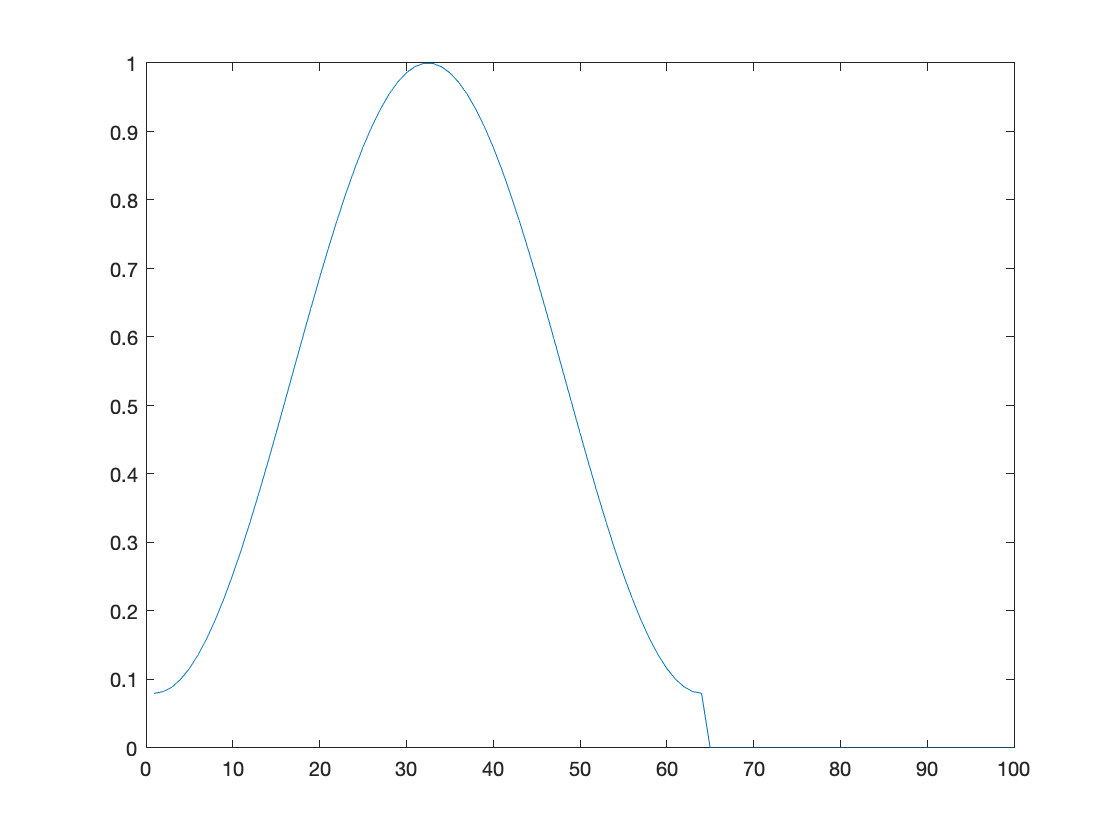

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A HAMMING WINDOW
w = [hamming(L);zeros(100-L,1)];
plot(w)

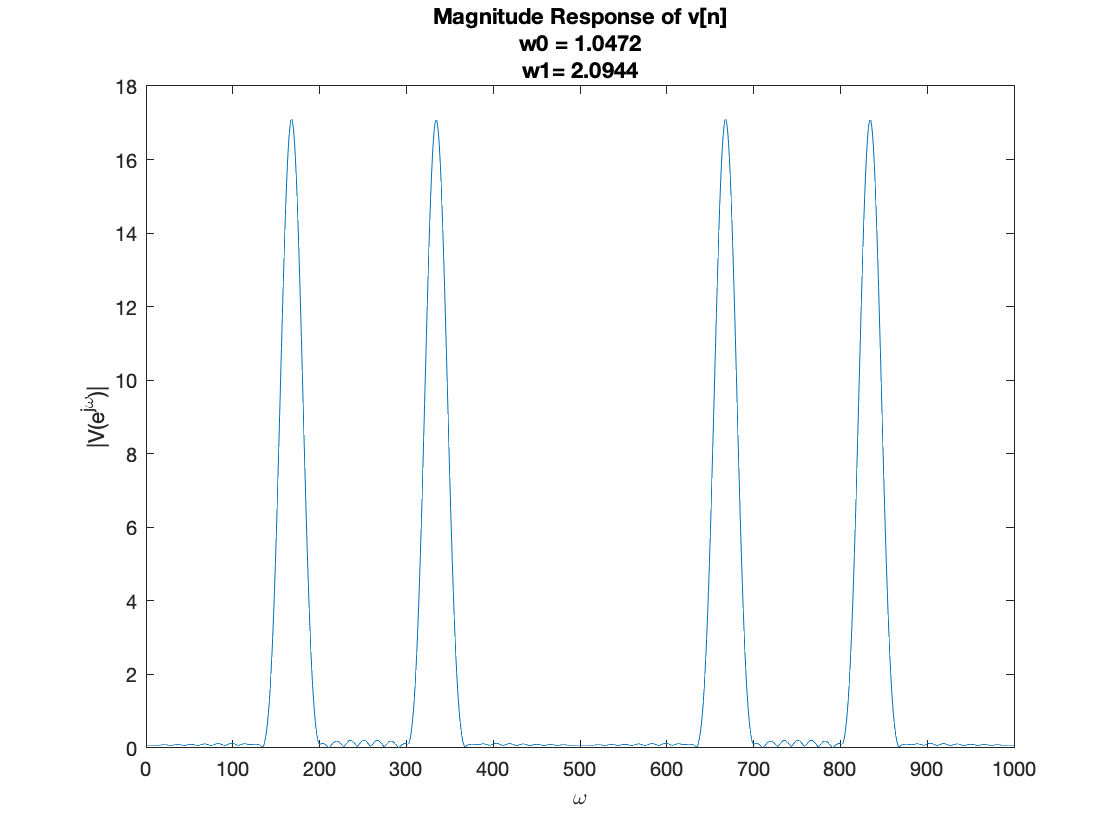

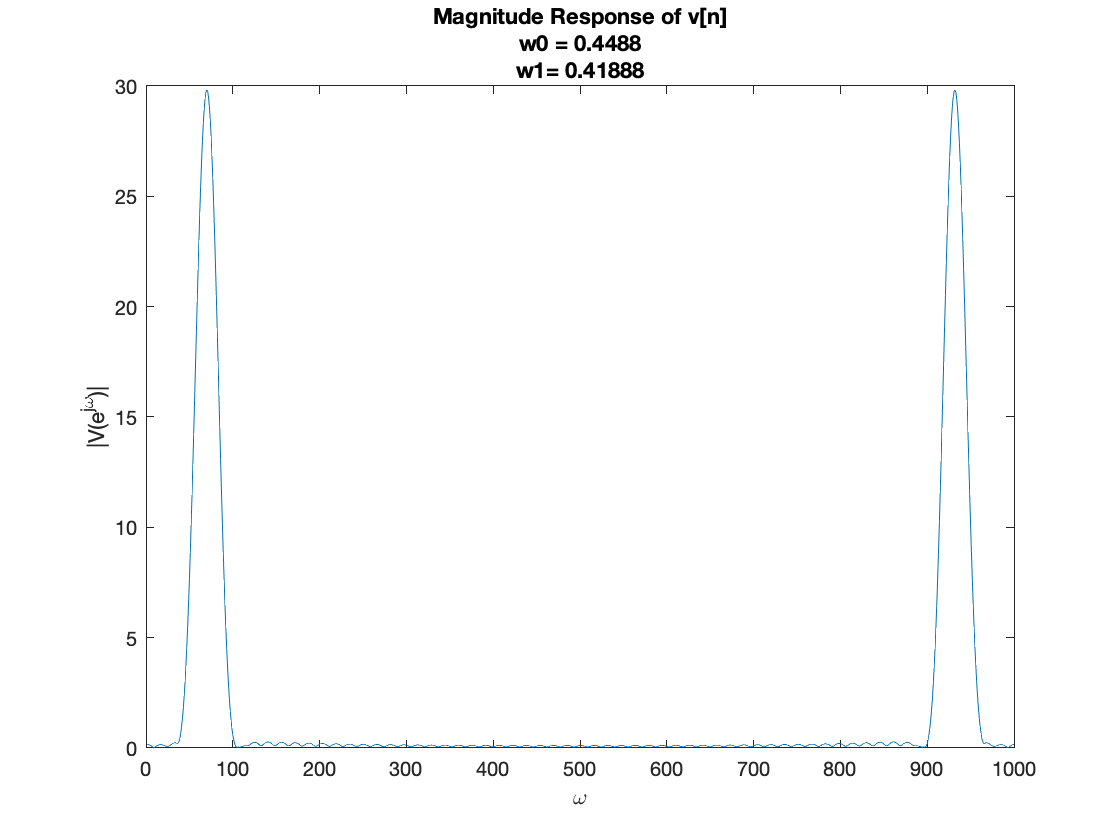

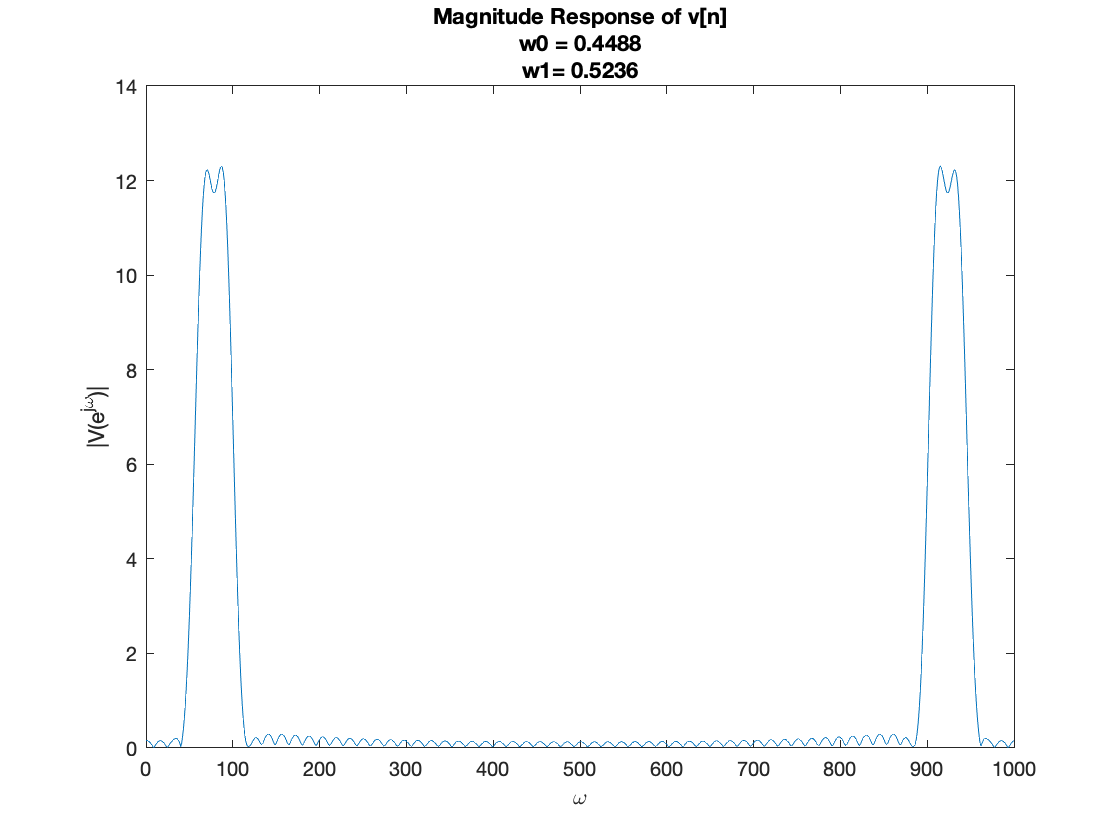

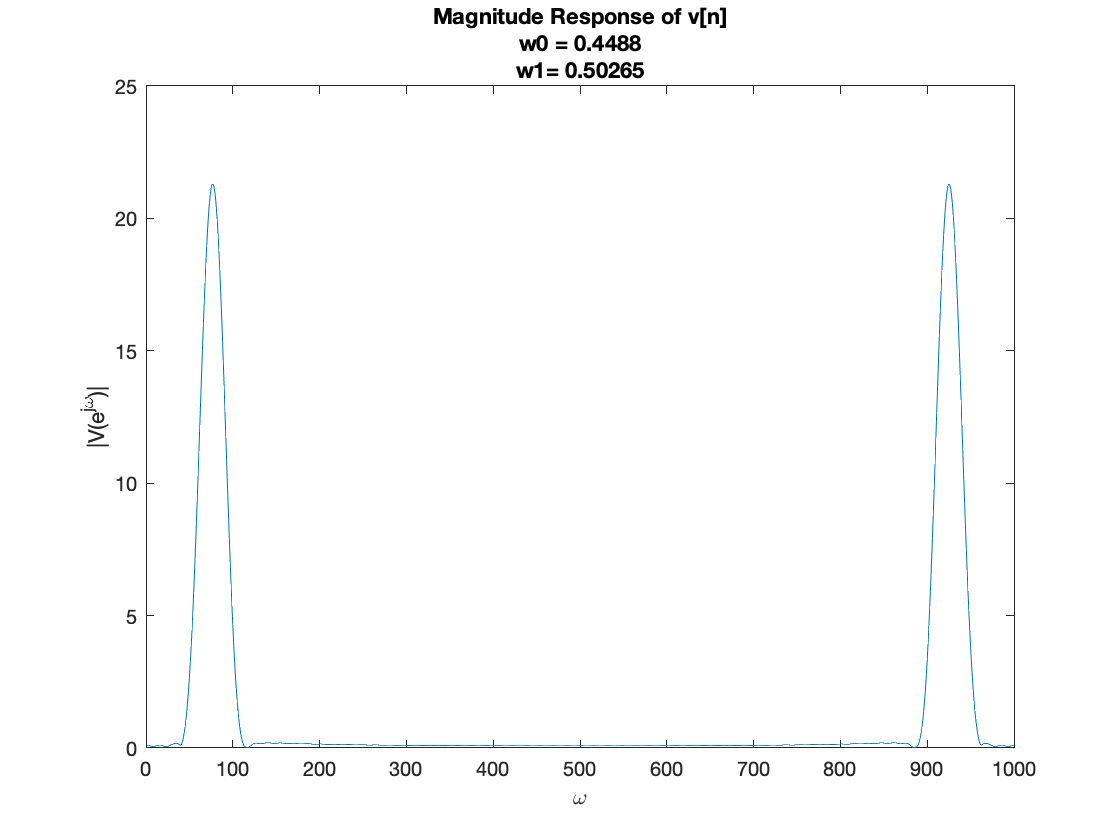

for i=1:size(x,1)
    x1 = x(i,:);
    v1 = x1.*w';
    figure();
    plot(abs(fft(v1,1000)))
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title({['Magnitude Response of v[n]'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

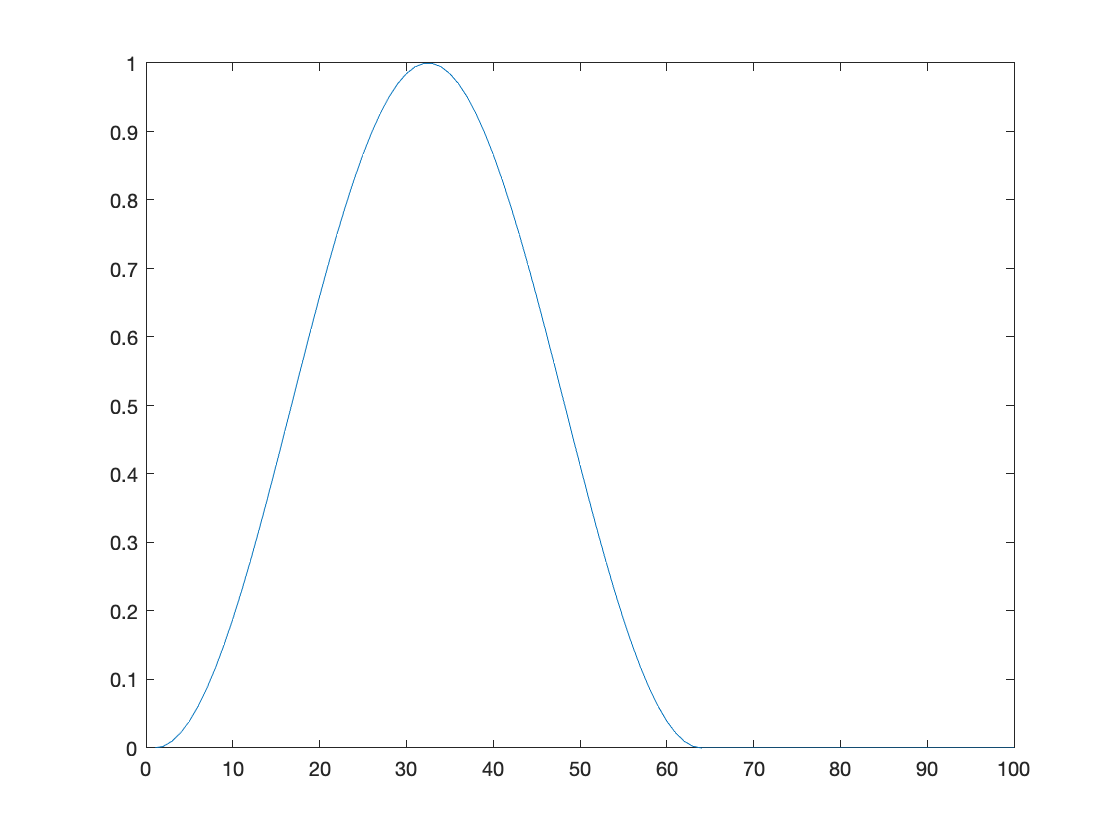

% COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Hanning WINDOW
w = [hann(L);zeros(100-L,1)];
plot(w)

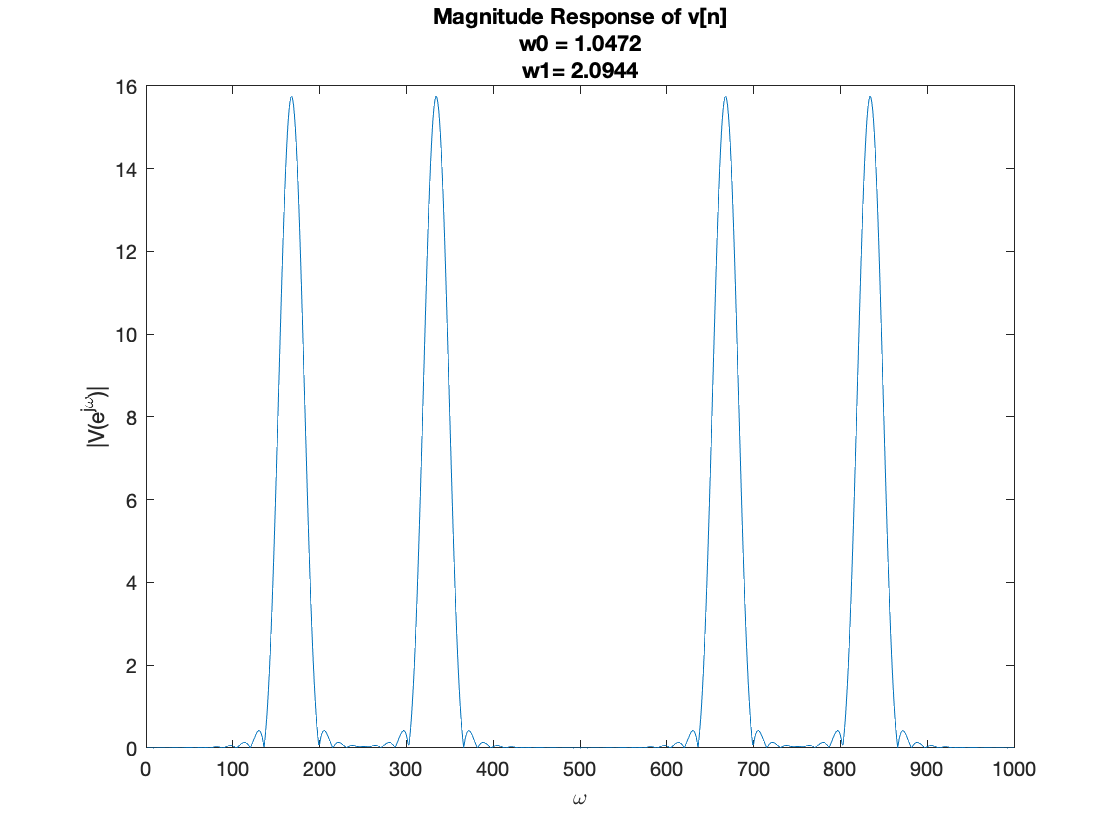

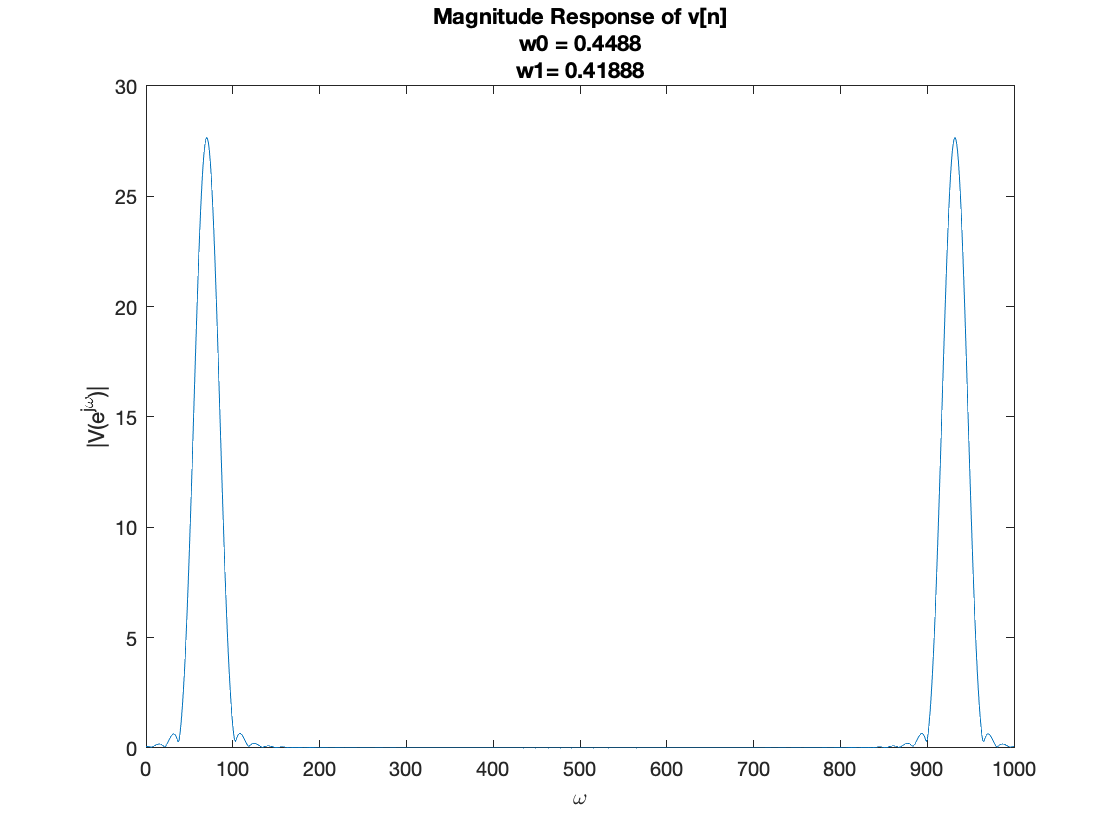

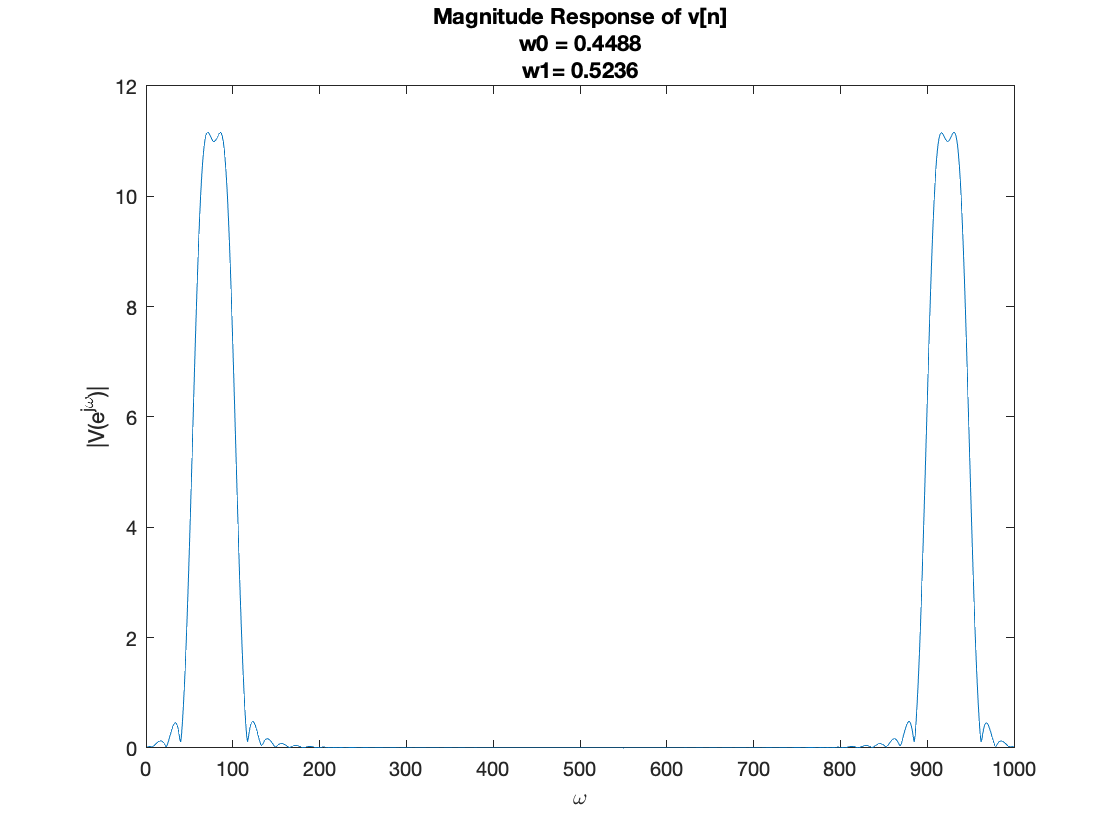

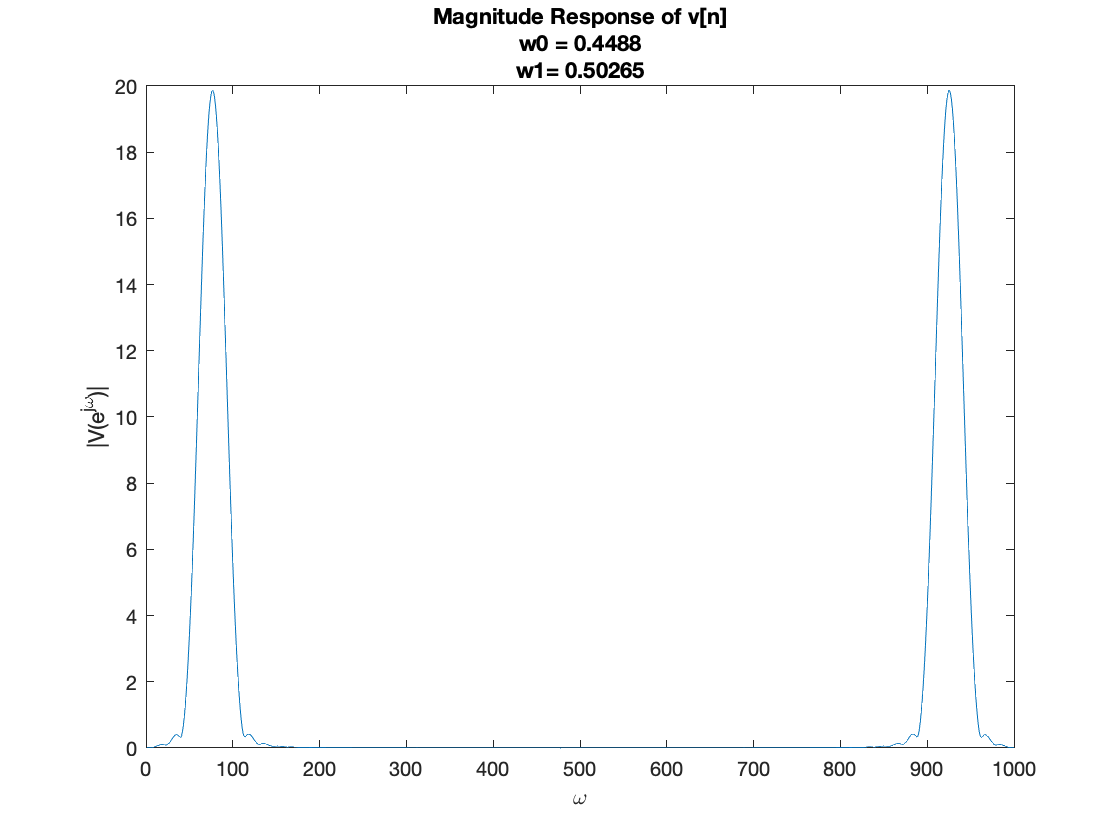

for i=1:size(x,1)
    x1 = x(i,:);
    v1 = x1.*w';
    figure();
    plot(abs(fft(v1,1000)))
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title({['Magnitude Response of v[n]'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

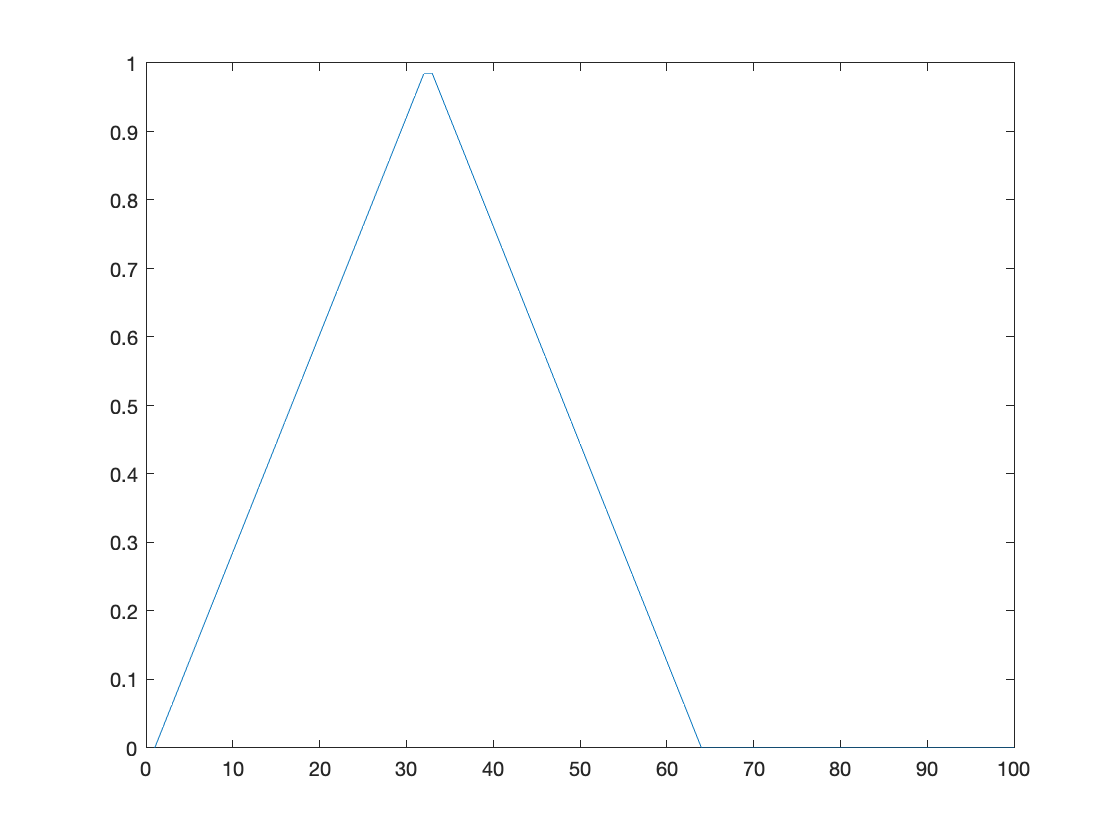

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Bartlet WINDOW
w = [bartlett(L);zeros(100-L,1)];
plot(w)

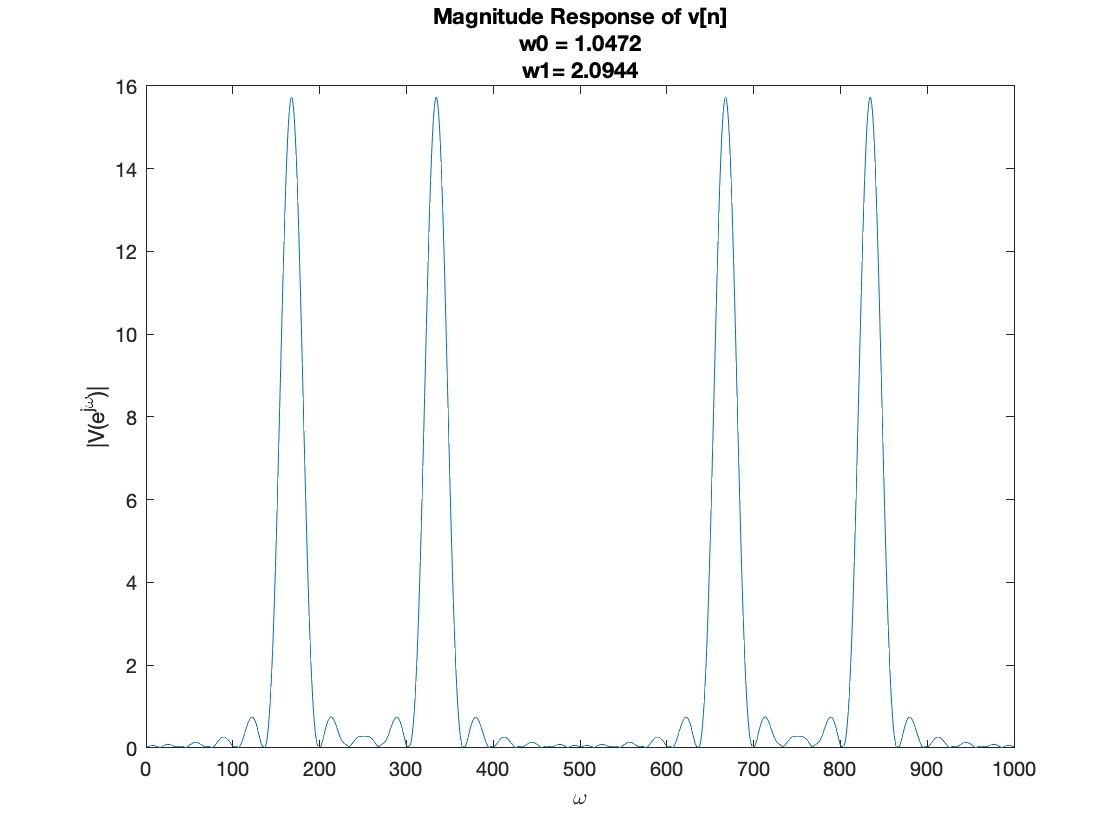

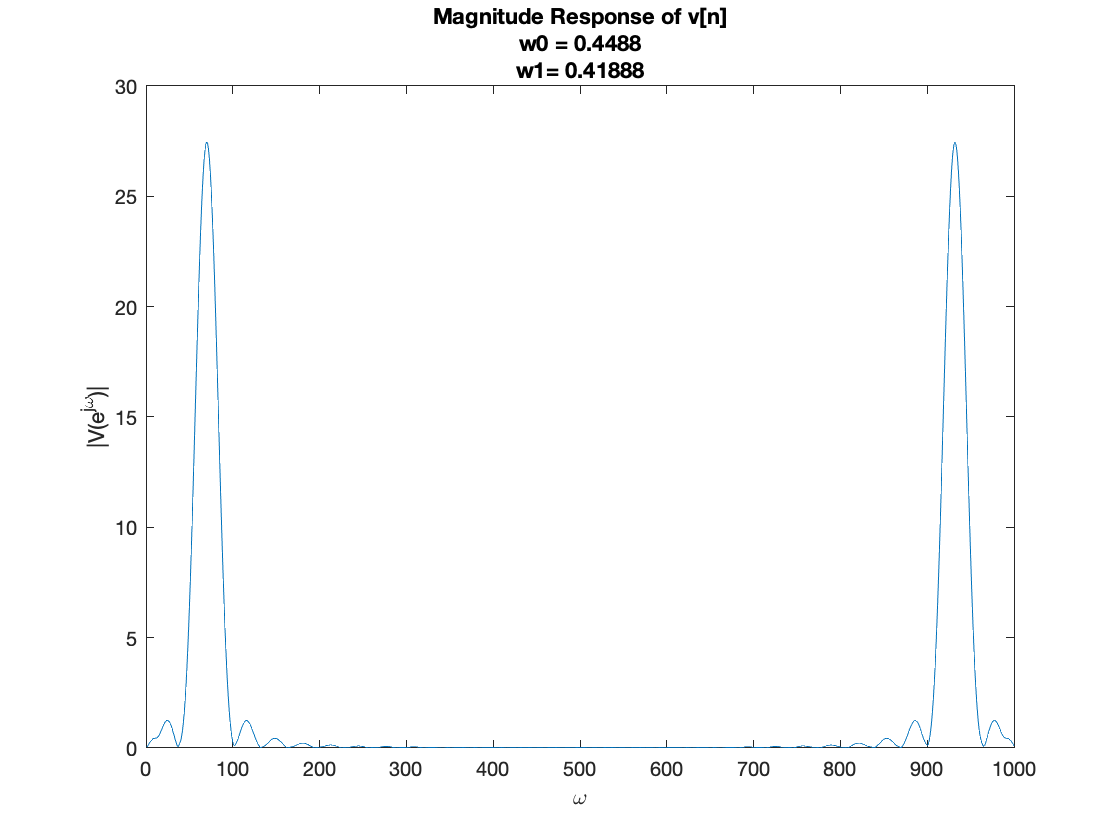

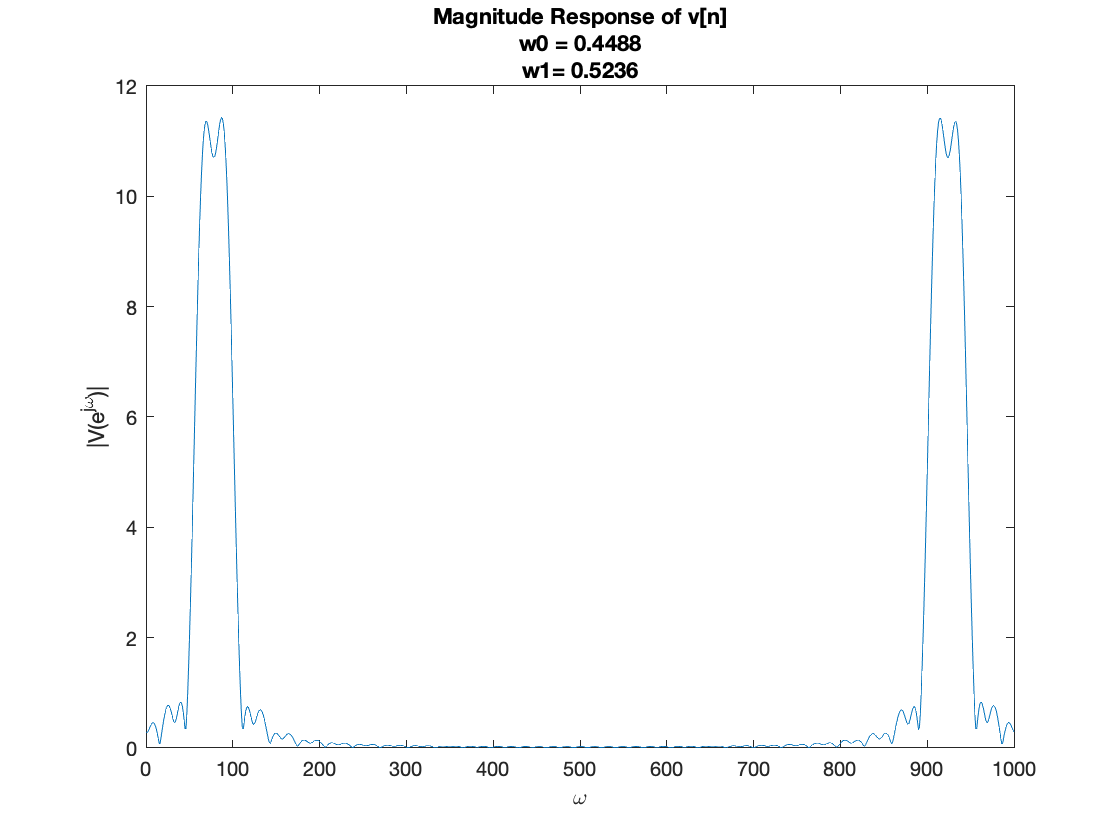

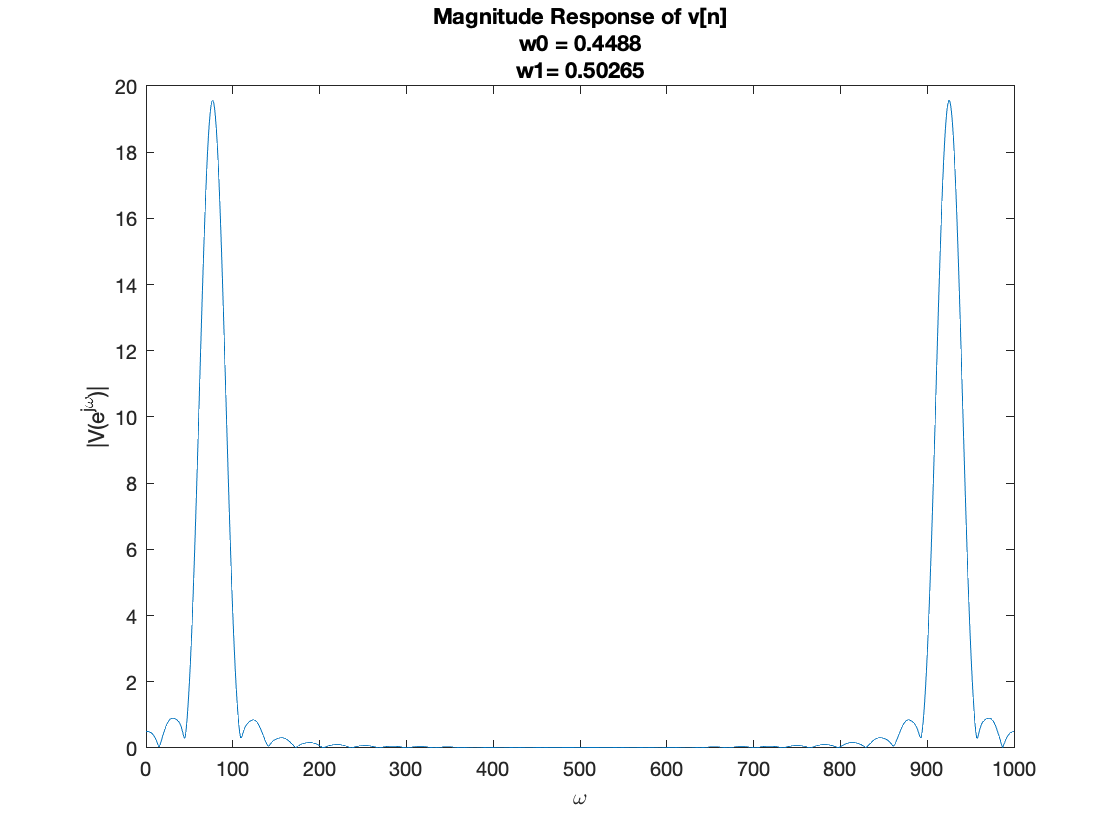

for i=1:size(x,1)
    x1 = x(i,:);
    v1 = x1.*w';
    figure();
    plot(abs(fft(v1,1000)))
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title({['Magnitude Response of v[n]'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

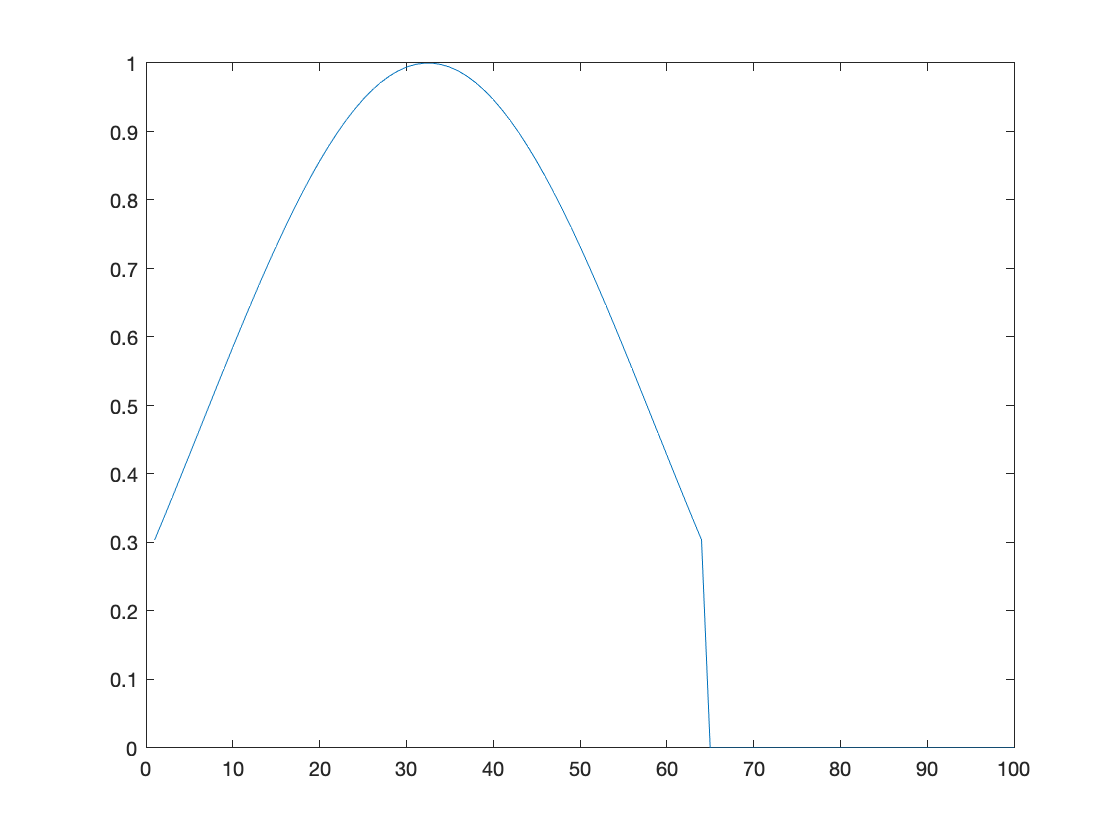

%  COMPUTE and PLOT DTFT OF v[n] WHEN w[n] IS A Kaiser WINDOW
w = [kaiser(L,2.5);zeros(100-L,1)];
plot(w)

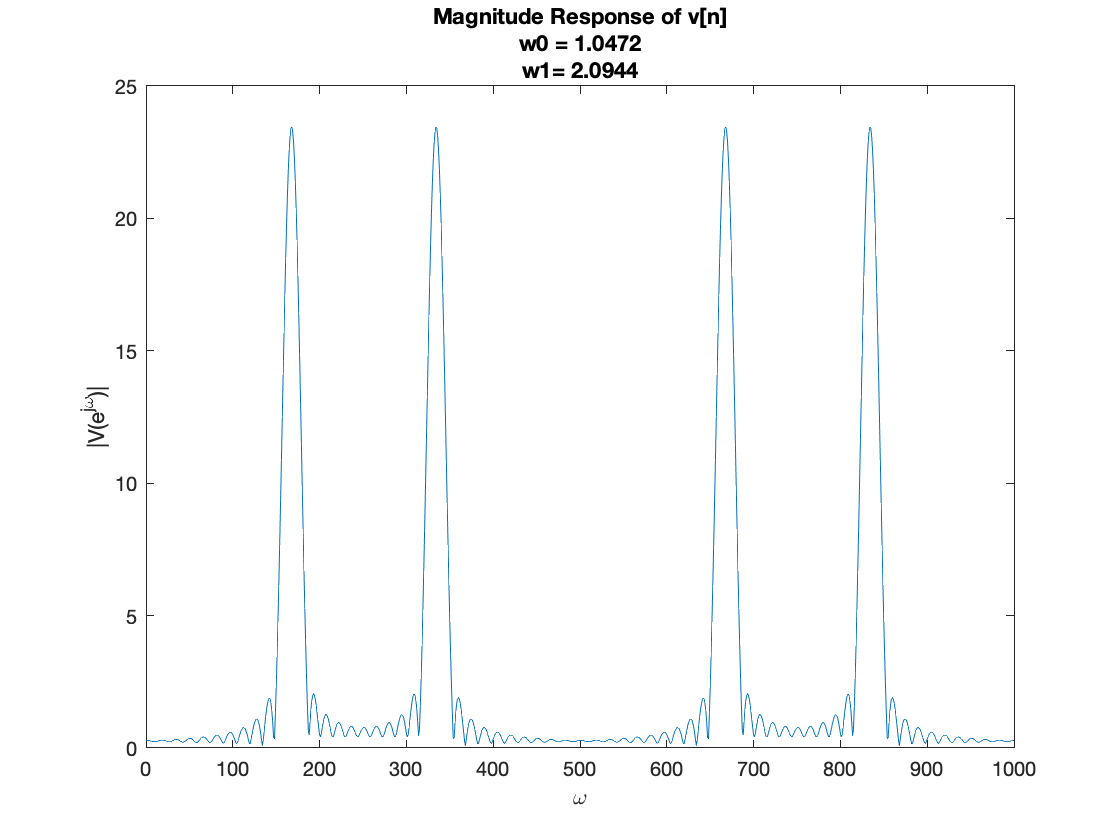

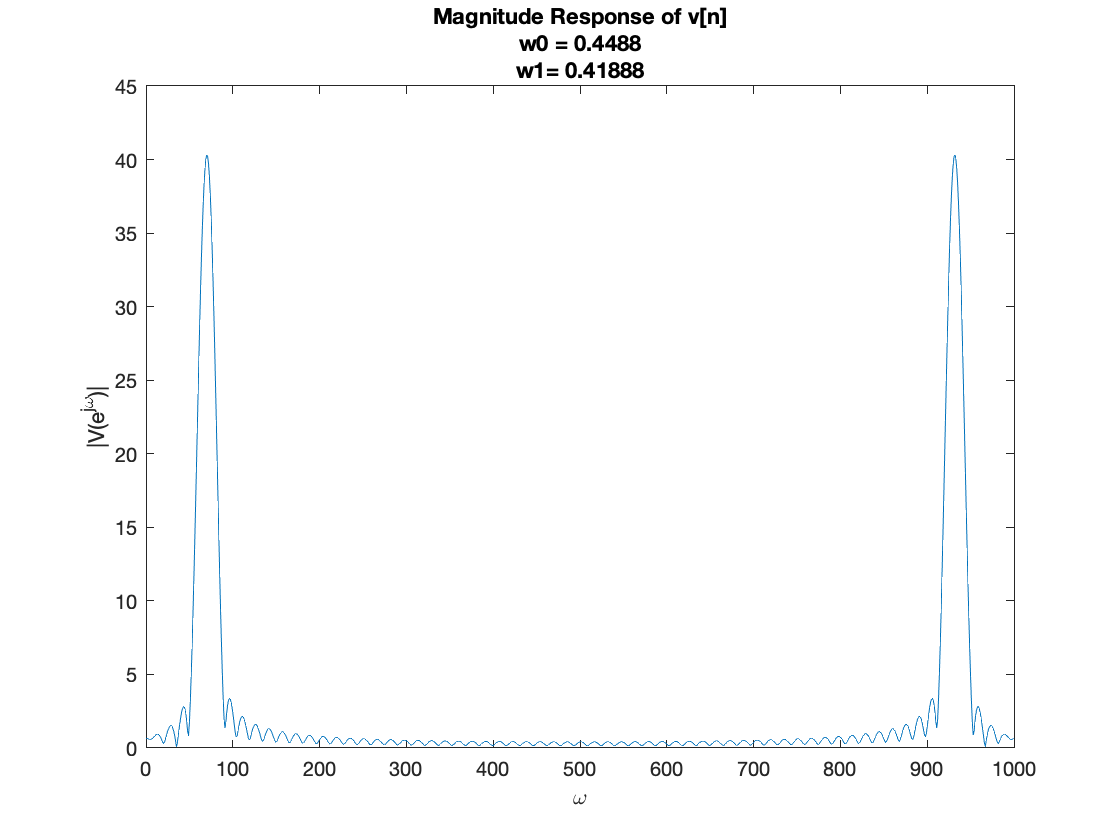

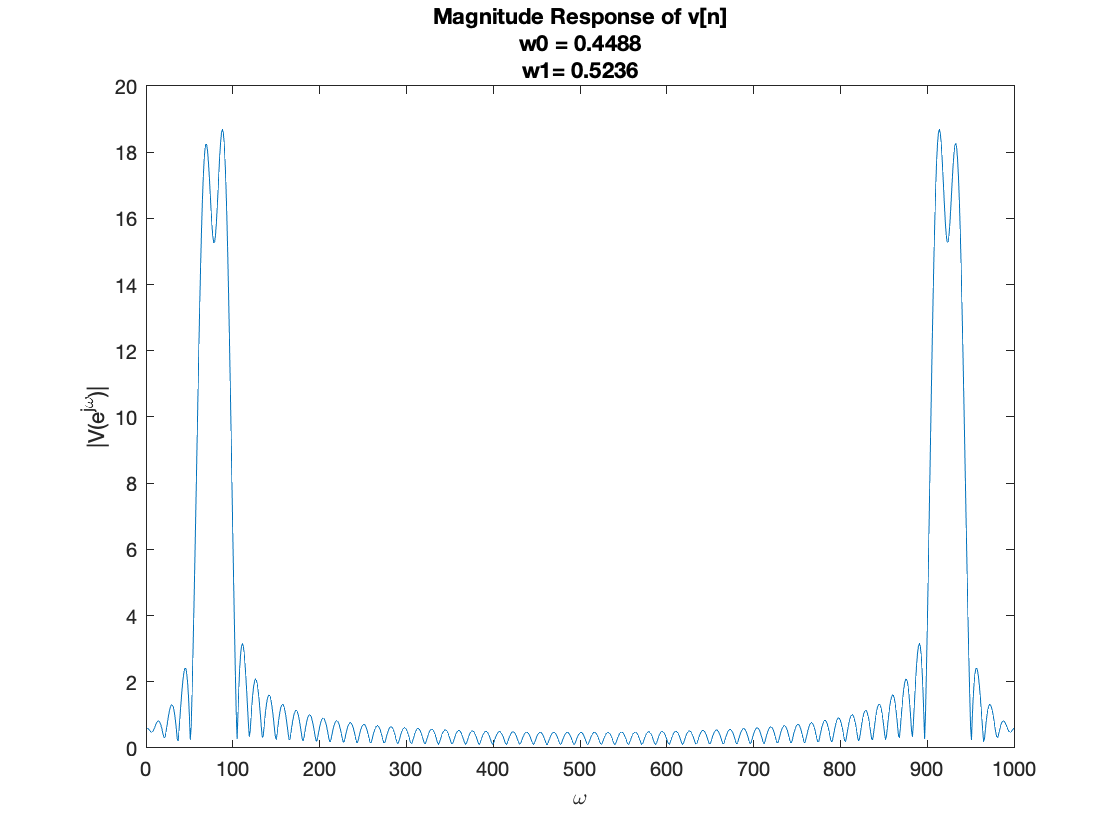

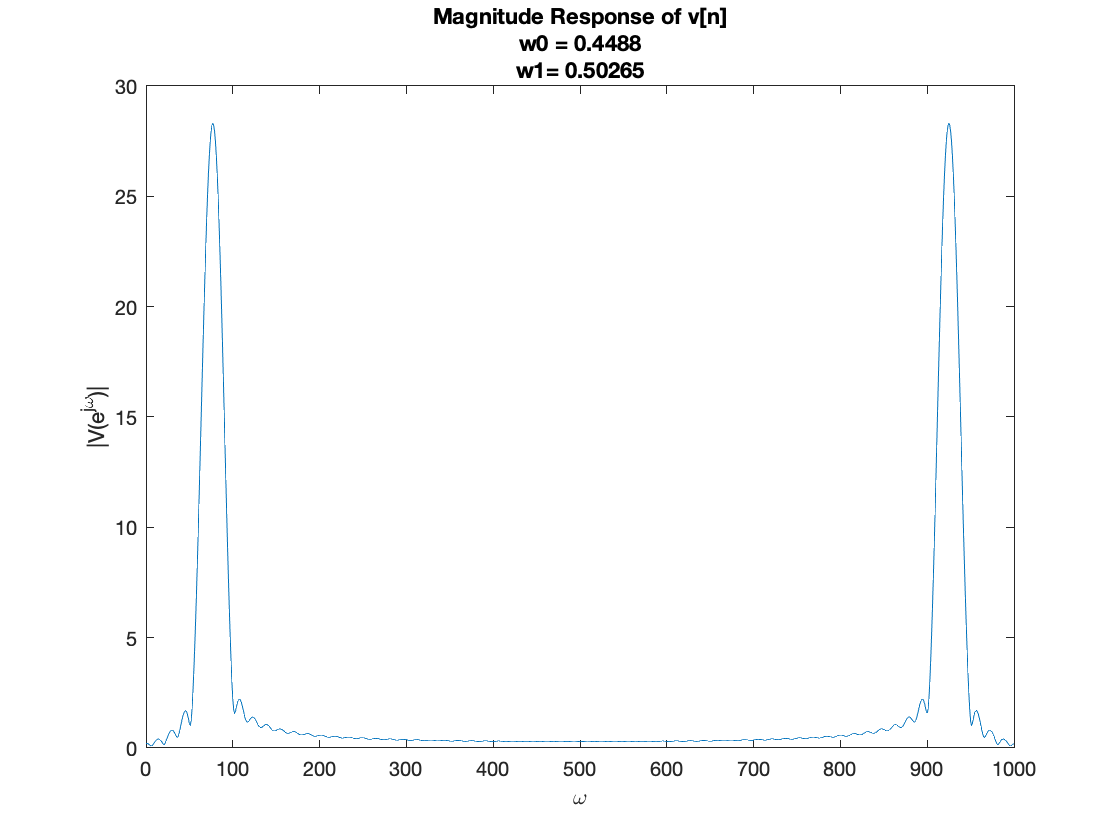

for i=1:size(x,1)
    x1 = x(i,:);
    v1 = x1.*w';
    figure();
    plot(abs(fft(v1,1000)))
    xlabel('\omega')
    ylabel('|V(e^{j\omega})|')
    title({['Magnitude Response of v[n]'];['w0 = ',num2str(w0(i))];['w1= ',num2str(w1(i))]})
end

#### Inference Question  (20 points)

- What do you observe on the number of peaks and their amplitudes?

- Give a short comparison of different windows on  the above terms (on the number of peaks and their amplitudes) that you can observe. 

    * WRITE YOUR ANSWER HERE.*

- The number of peaks depend upon the values of $w_0,w_1$ as if the difference between them is lesser than the window signal DTFT then the peaks will get superimposed and we will observe lesser number of peaks than there should be.

- Number of Peaks:Hamming=Hanning=Bartlett<Kaiser

- Main Lobe ampltude:Bartlett<Hanning<Hamming<Kaiser

- Side Lobe Amplitude:Hamming=Hanning<Bartlett<Kaiser

## Short-Time Fourier Transform (50 Points)

In the above material, we assume that the frequencies and amplitudes of the sinusoids do not change with time. However, in practice, usually amplitudes and frequencies of a signal change with time. For analyzing the frequency content of that we consider only a small window and analyse its frequency content, and slide the window to look at the frequency content of the next window and so on. This is called the Short-Time Fourier Transform. 

Now read the first page of Section 10.3 of "Discrete-Time Signal Processing", 2nd Edition by Alan V. Oppenheim, Ronald Schafer and John R. Buck. 

- How is the short-time Fourier transform defined as, for a sequence $x[n]$.

        ANSWER:  $ ENTER~YOUR~ANSWER~HERE$

                            $X[n,\lambda) = \sum_{m=-\infty}^{\infty}x[n+m]w[m]e^{-j\lambda m} $ , $\lambda \in [0,2\pi]
$

                             $X[n,\lambda)
$ can be interpreted as the DTFT of the shifted signalx[n +m], as viewed through the window w[m].

- Now, construct the following frequency modulated chirp signal: $x[n] = \cos(\omega_0 n^2), $ where $\omega_0 = 2\pi\times 7.5\times10^{-6}. $

x = [] % ENTER YOUR CODE HERE


x =

     []



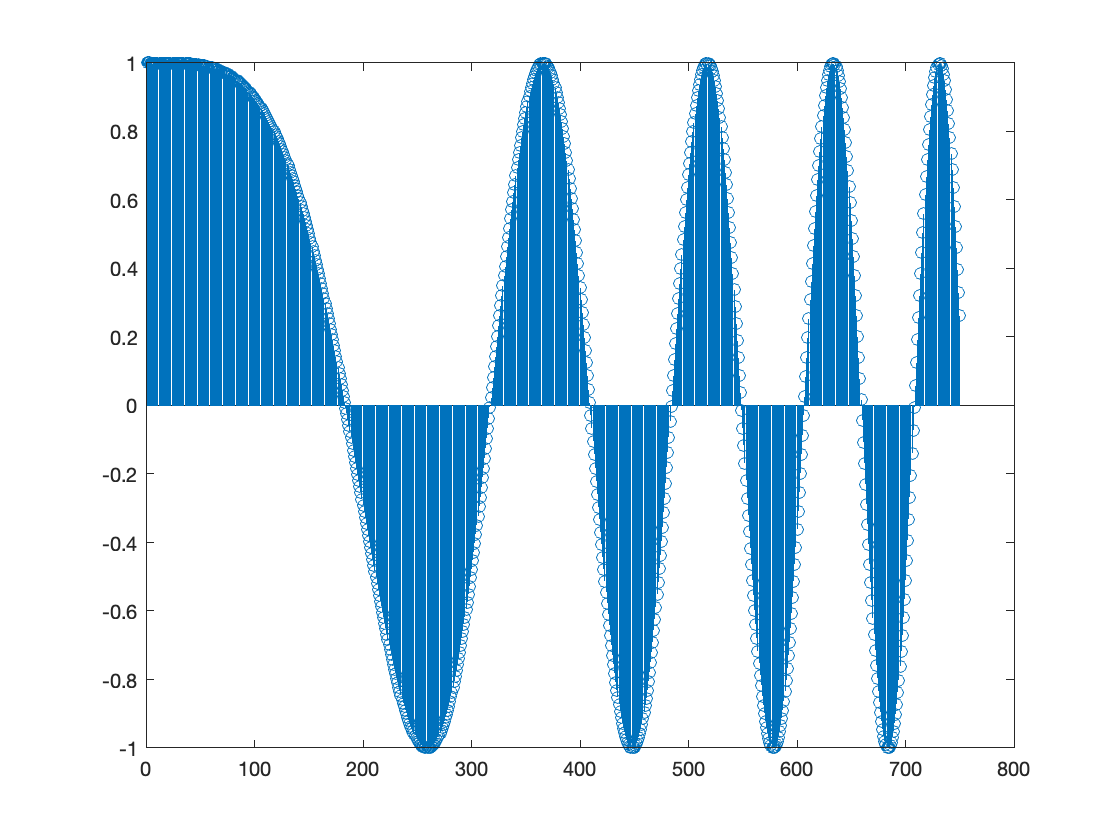

omega_not = 2*pi*(7.5)*10^-6;
n = 0:1:10000;
x = cos(omega_not*n.^2);
stem(x(1:750))

- Now compute the short-term Fourier transform of $x[n], $ with rectangular window, $w[n]$  of some L  length. 

L  = [250] % LENGTH OF THE RECTANGULAR WINDOW

L = 250

w = []; % RECTANGULAR WINDOW
w = [ones(L,1);zeros(size(x,2)-L,1)];
X = []; % COMPUTE STFT of x[n] using rectnagluar window w[n].
             % DISPLAY THE IMAGE IN A TWO DIMENSIONAL PLOT. 
lambda = 0:2*pi/1000:2*pi;
X = zeros(750,length(lambda));
for i=1:750
    for j=1:length(lambda)
        for k=1:2000
                X(i,j) = X(i,j) + x(i+k)*w(k)*exp(-1j*lambda(j)*(k-1));
        end
    end
end

X;

- Now use [spectrogram](https://in.mathworks.com/help/signal/ref/spectrogram.html) to compute the short-time Fourier transform of the above $x[n]$ and compare it with what you had got. 

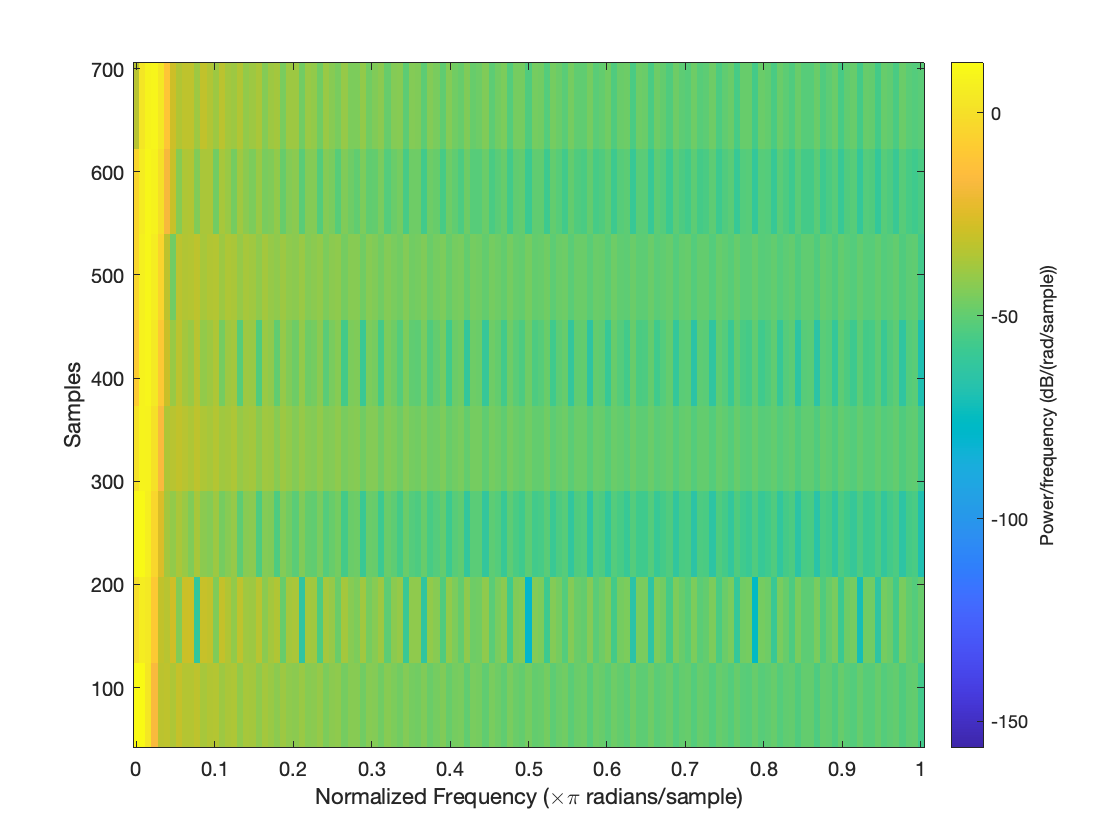

%WRITE YOUR CODE HERE

spectrogram(x(1:750))

# Practical Experiment (50 Points)

- Now count 1 to 5 in any language of your interest (try your mother tongue) and record it.

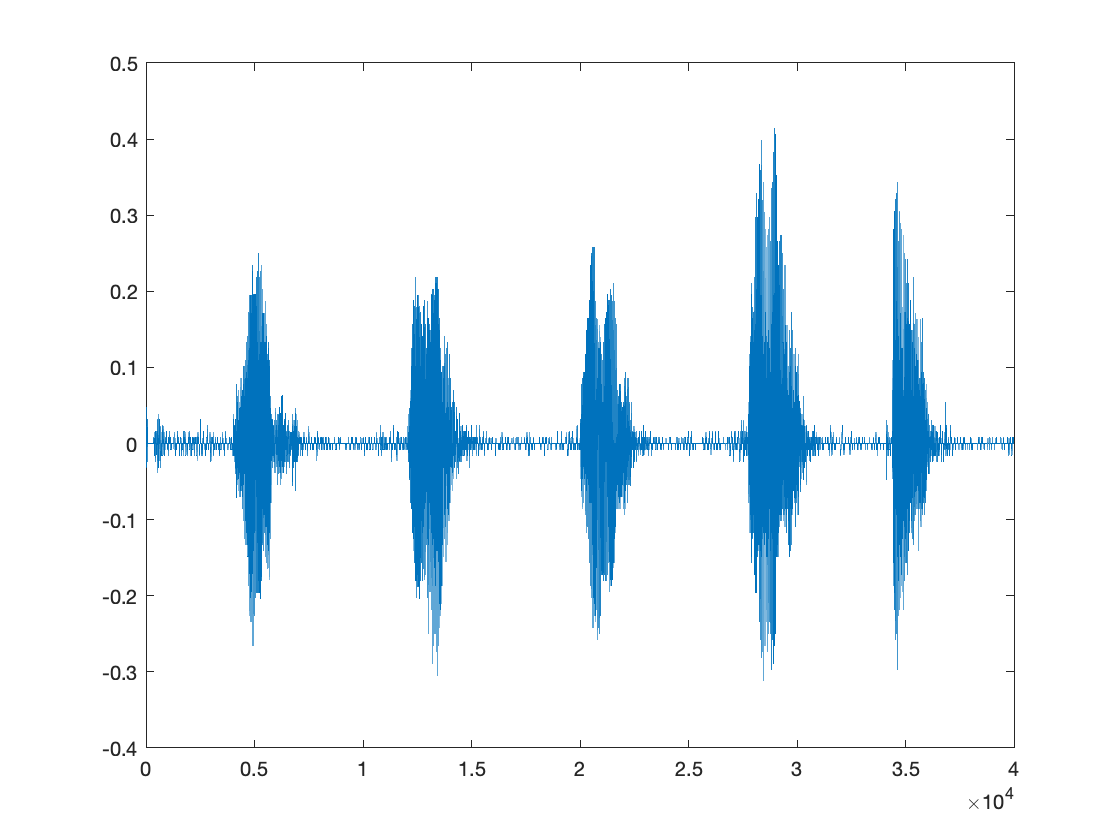

% COUNT 1-5 AND RECORD IT.
recorder = audiorecorder;
recordblocking(recorder,5);
x = getaudiodata(recorder);
plot(x)

- Now compute the spectrogram of the signal you have recorded

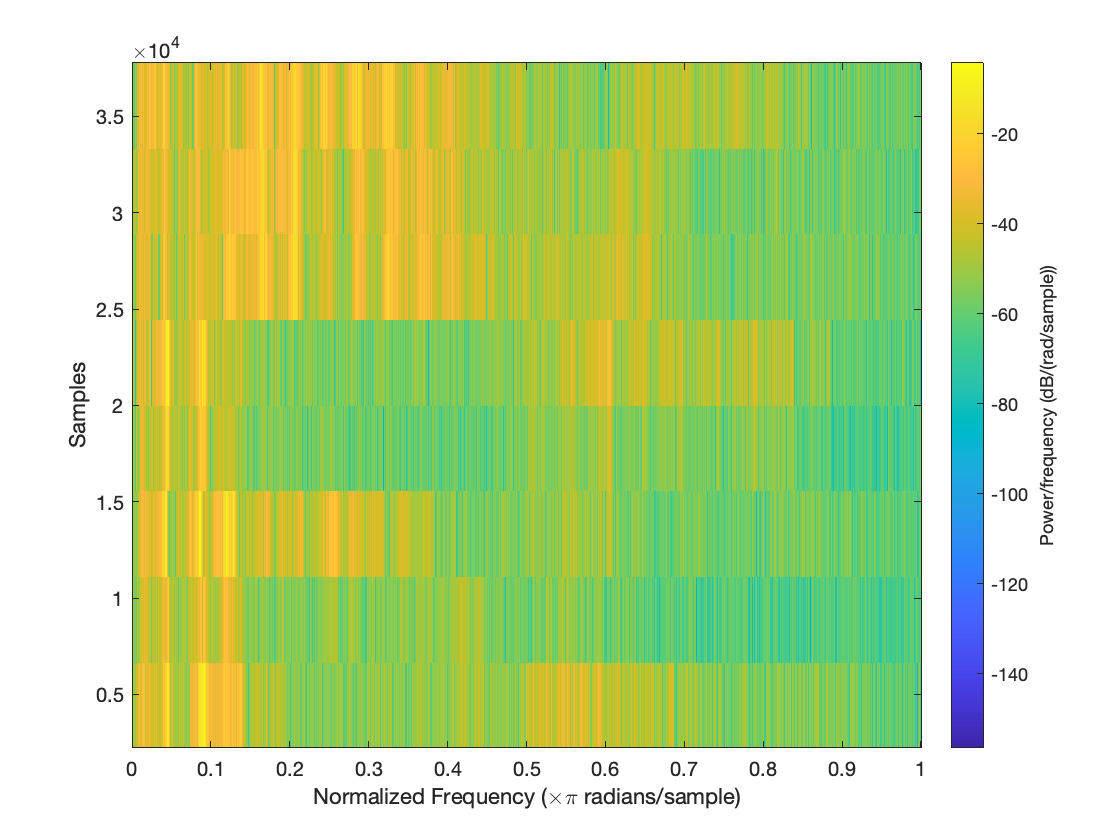

% COMPUTE THE SPECTROGRAM
spectrogram(x)

- Play with different parameters of the spectrogram and write your 3 observations: 

        ANSWER: 

- Now compute the [periodogram](https://in.mathworks.com/help/signal/ref/periodogram.html) of the recorded signal:

%WRITE YOUR CODE HERE

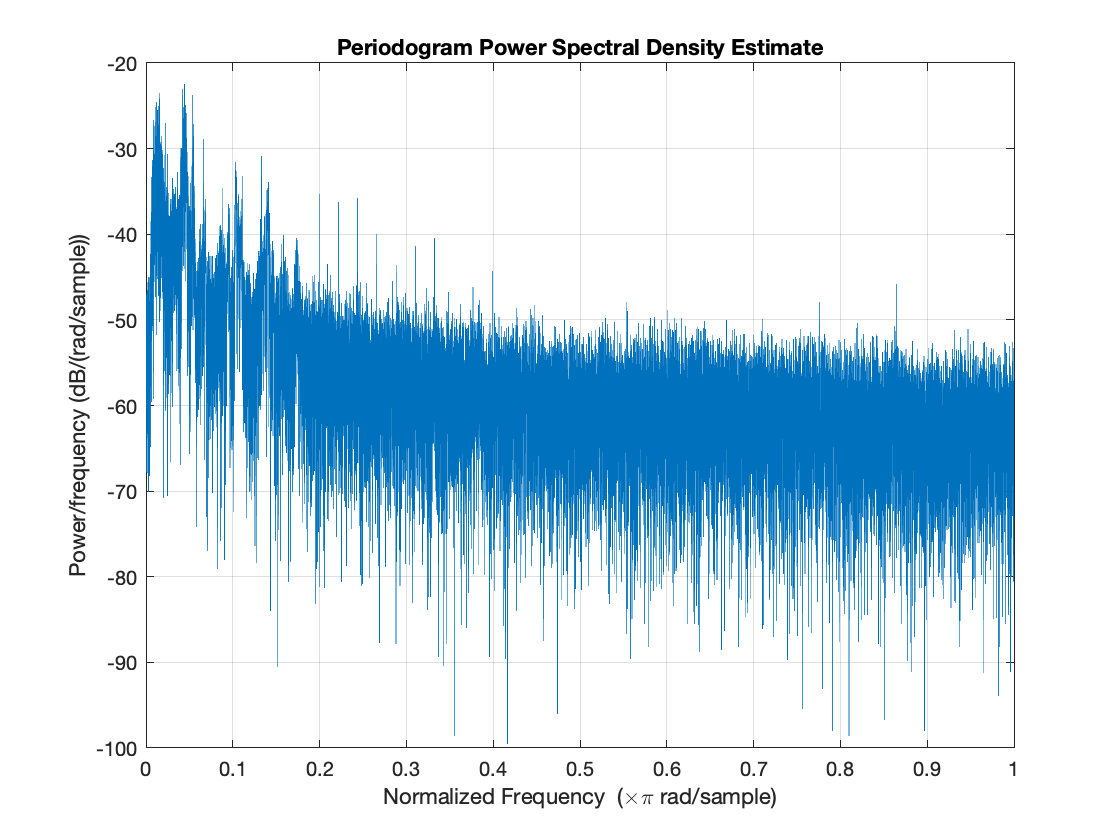

periodogram(x)

- What information does the periodogram give? 

        ANSWER: A periodogram is used to identify the dominant periods (or frequencies) of a time series. 

- Until what frequency does human voice contain significant power density? 

        ANSWER: 155 Hz for male and 255 Hz for female

## Thank You!